# **Optimising Recruitment and Sample Allocation in Multi-Site Rare**

# **Disease Studies**


$$\text{Farid Zare}^{1,2}, \text{Catherine Clancy}^{1,2}, \text{Tal Dattner}^{3},  \text{Stefan Kölker}^{3}, \text{Ronan M.T. Fleming}^{1,2}

$$



$$^1\text{Digital Metabolic Twin Centre, University of Galway, Galway, Ireland};\ ^2\text{School of Medicine, University of Galway, University Rd, Galway, Ireland};\ ^3\text{Medical Faculty, University Hospital Heidelberg, Center for Child and Adolescent Medicine, Division of Pediatric Neurology and Metabolic Medicine, Heidelberg University, Heidelberg, Germany};$$


## Requirements:

- COBRA Toolbox should be installed to solve the cardinality optimisation problem

- A solver must be installed to solve the mathematical model. Here, the GUROBI solver is used and tested.

## Define data folder

% Clean previous data
clear

path = matlab.desktop.editor.getActiveFilename;

mainFolder = fileparts(fileparts(path));
% Add the folder and the subfolders to the MATLAB path
addpath(genpath(mainFolder));

dataFolder = fullfile(mainFolder, 'data');

## Define result folder

resultFolder = fullfile(mainFolder, 'results');

## Define graphic folder

graphicFolder = fullfile(mainFolder, 'graphics');

## Selected Inherited Metabolic Diseases in the Recon4IMD project

## Load ICIMD Gene OMIM number

% Load ICIMD gene symbols
icimdGeneData = readtable(fullfile(dataFolder, 'GeneData.xlsx'), 'Sheet', 'ICIMD','ReadVariableNames', true, 'VariableNamingRule', 'preserve');
icimdGeneSym = icimdGeneData.GeneName;
icimdGeneSym = rmmissing(icimdGeneSym); %remove empty cells

% Load VMH gene symbols
vmhGeneData = readtable(fullfile(dataFolder, 'GeneData.xlsx'), 'Sheet', 'vmhGenes','ReadVariableNames', true, 'VariableNamingRule', 'preserve');
vmhGeneSym = vmhGeneData.symbol;
vmhGeneSym = rmmissing(vmhGeneSym); %remove empty cells

% Load IEMbase gene symbols
iembaseData = readtable(fullfile(dataFolder, 'IEMbase_fz.xlsx'), 'ReadRowNames', false, 'ReadVariableNames', true);
iembaseGeneSym = iembaseData.GeneSymbol;
iembaseGeneSym = rmmissing(iembaseGeneSym); %remove empty cells

## Venn diagram for ICIMD VMH and IEMbase genes using gene symbols as namespace

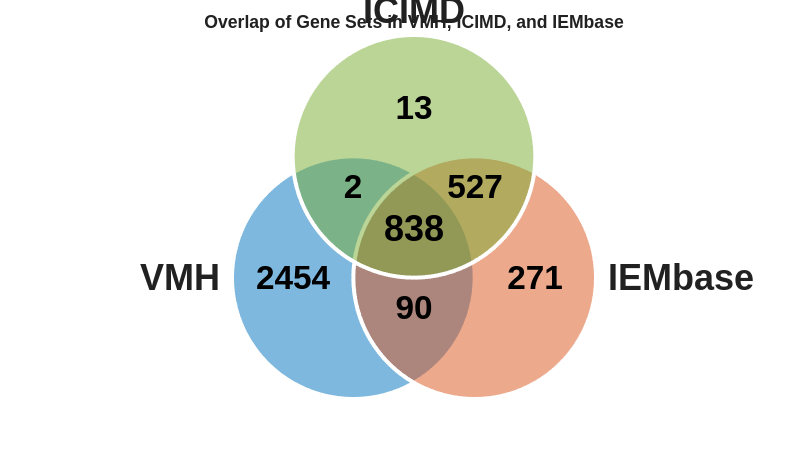

% icimd = A, reconX = B, IEMbase = C,

A = unique(icimdGeneSym);
B = unique(vmhGeneSym);
C = unique(iembaseGeneSym);

% Compute intersection counts
An = length(setdiff(A, union(B, C)));           % Only in A
Bn = length(setdiff(B, union(A, C)));           % Only in B
Cn = length(setdiff(C, union(A, B)));           % Only in C
ABn = length(intersect(A, B)) - length(intersect(intersect(A, B), C));  % A ∩ B only
ACn = length(intersect(A, C)) - length(intersect(intersect(A, B), C));  % A ∩ C only
BCn = length(intersect(B, C)) - length(intersect(intersect(A, B), C));  % B ∩ C only
ABCn = length(intersect(intersect(A, B), C));    % A ∩ B ∩ C 

mysets = ["ICIMD" "VMH" "IEMbase"];
mylabels = [An, Bn, Cn, ABn, ACn, BCn, ABCn];
% Define colors
c = [0 0.4470 0.7410;   % Blue
     0.8500 0.3250 0.0980; % Red
     0.4660 0.6740 0.1880];% Green

vennFig = venn4(3,'sets',mysets,'labels',mylabels,'colors',c,'alpha',0.5,'edgeC',[1 1 1],'edgeW',3, 'fontSize', 25);
title("Overlap of Gene Sets in VMH, ICIMD, and IEMbase", 'FontWeight', 'bold', 'FontSize', 20);
set(gca, 'FontName', 'Arial');

% Set aspect ratio to be equal to avoid distortion
axis equal;

## Mapp Genes to IMDs

ABC = intersect(intersect(A, B), C);
IMDGeneid = ismember(iembaseData.GeneSymbol, ABC);
feasibleIMDs = unique(iembaseData.IEMNosologyCode(IMDGeneid));
fprintf('%s%d%s%d', 'Total number of IMDs in the IEMbase: ', numel(unique(C)));

Total number of IMDs in the IEMbase: 1726

fprintf('%s%d%s%d', 'A total of ', numel(ABC), ' causal genes corresponds to ', numel(feasibleIMDs), ' IMDs according to the IEMbase databse')

A total of 838 causal genes corresponds to 897 IMDs according to the IEMbase databse

## Mapp genes to metabolites

metaboliteSet = unique(iembaseData.IEMbaseHMDB(IMDGeneid));
fprintf('%s%d%s%d', 'A total of ', numel(ABC), ' causal genes corresponds to ', numel(metaboliteSet), ' unique metabolite biomarkers according to the IEMbase databse')

A total of 838 causal genes corresponds to 416 unique metabolite biomarkers according to the IEMbase databse

## Venn diagram for metabolites VMH, Metabolomic platforms, and selected genes

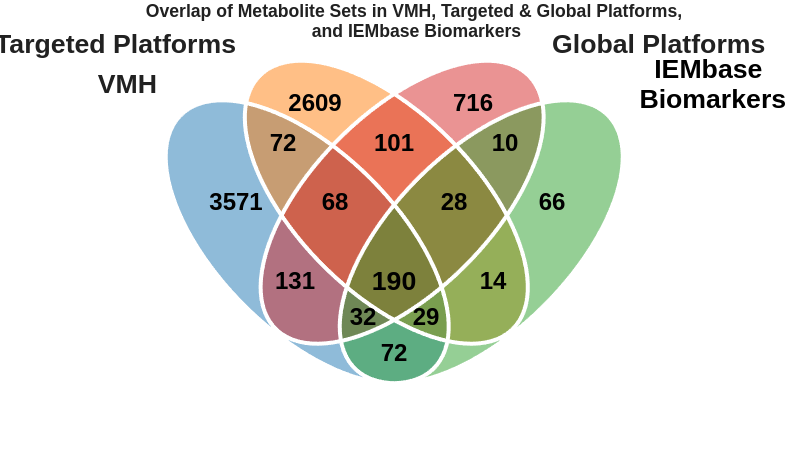

% Load VMH metabolites
vmhMetabolitesData = readtable(fullfile(dataFolder, 'vmhMetabolites.xlsx'),'ReadVariableNames', true, 'VariableNamingRule', 'preserve');
vmhMetabolitesMetanetx = vmhMetabolitesData.MetaNetX;

% Load targeted platforms data
targetedPlatformsData = readtable(fullfile(dataFolder, 'AllCentresMetabolites.xlsx'),'ReadVariableNames', true, 'Sheet', 'Targeted', 'VariableNamingRule', 'preserve');
targetedPlatformsMetanetx = targetedPlatformsData.MetaNetX;

% Load global platforms data
globalPlatformsData = readtable(fullfile(dataFolder, 'AllCentresMetabolites.xlsx'),'ReadVariableNames', true, 'Sheet', 'Global', 'VariableNamingRule', 'preserve');
globalPlatformsMetanetx = globalPlatformsData.MetaNetX;

% Load IEMbase Metabolites
IEMbaseMetabolitesData = readtable(fullfile(dataFolder, 'IMD_mapped.xlsx'),'ReadVariableNames', true, 'VariableNamingRule', 'preserve');
IEMbaseMetabolitesMetanetx = IEMbaseMetabolitesData.MetaNetX;

A = unique(rmmissing(vmhMetabolitesMetanetx));
B = unique(rmmissing(targetedPlatformsMetanetx));
C = unique(rmmissing(globalPlatformsMetanetx));
D = unique(rmmissing(IEMbaseMetabolitesMetanetx));

% Compute sizes of individual sets
An   = numel( setdiff( A, union( union(B, C), D ) ) );              % Only A
Bn   = numel( setdiff( B, union( union(A, C), D ) ) );              % Only B
Cn   = numel( setdiff( C, union( union(A, B), D ) ) );              % Only C
Dn   = numel( setdiff( D, union( union(A, B), C ) ) );              % Only D

% Compute sizes of pairwise intersections
ABn = numel(setdiff(intersect(A, B), union(C, D)));
ACn = numel(setdiff(intersect(A, C), union(B, D)));
ADn = numel(setdiff(intersect(A, D), union(B, C)));
BCn = numel(setdiff(intersect(B, C), union(A, D)));
BDn = numel(setdiff(intersect(B, D), union(A, C)));
CDn = numel(setdiff(intersect(C, D), union(A, B)));

% Compute sizes of triple intersections
ABCn = numel(setdiff(intersect(A, intersect(B, C)), D));
ABDn = numel(setdiff(intersect(A, intersect(B, D)), C));
ACDn = numel(setdiff(intersect(A, intersect(C, D)), B));
BCDn = numel(setdiff(intersect(B, intersect(C, D)), A));

% Compute size of the quadruple intersection
ABCD = intersect(A, intersect(B, intersect(C, D)));
ABCDn = numel(ABCD);

mysets = ["VMH" "Targeted Platforms" "Global Platforms" sprintf("   IEMbase \n Biomarkers")];
mylabels = [An, Bn, Cn, Dn, ABn, ACn, ADn, BCn, BDn, CDn, ABCn, ABDn, ACDn, BCDn, ABCDn];

% Define colors
c = [0.1216 0.4667 0.7059;   % #1f77b4 (Blue)
    1.0000 0.4980 0.0549;    % #ff7f0e (Orange)
    0.8392 0.1529 0.1569;    % #d62728 (Red)
    0.1725 0.6275 0.1725];   % #2ca02c (Green)


vennFig = venn4(4,'sets',mysets,'labels',mylabels,'colors',c,'alpha',0.5,'edgeC',[1 1 1],'edgeW',3, 'fontSize', 18);
title(sprintf("Overlap of Metabolite Sets in VMH, Targeted & Global Platforms,\n and IEMbase Biomarkers"), 'FontWeight', 'bold', 'FontSize', 20);
set(gca, 'FontName', 'Arial');

## IMDs with modellable genes and metabolites and measurable metabolite biomarkers

IMDMetaboliteID = ismember(IEMbaseMetabolitesMetanetx, ABCD);

candidateIMDs = unique(iembaseData.IEMNosologyCode(IMDMetaboliteID & IMDGeneid)); 
fprintf('%s%d', 'Number of IMDs with modellable genes and atleast one moedllable and measurable metabolite biomarker: ', numel(candidateIMDs))

Number of IMDs with modellable genes and atleast one moedllable and measurable metabolite biomarker: 365

## Selected Inherited Metabolic Diseases in the Recon4IMD project

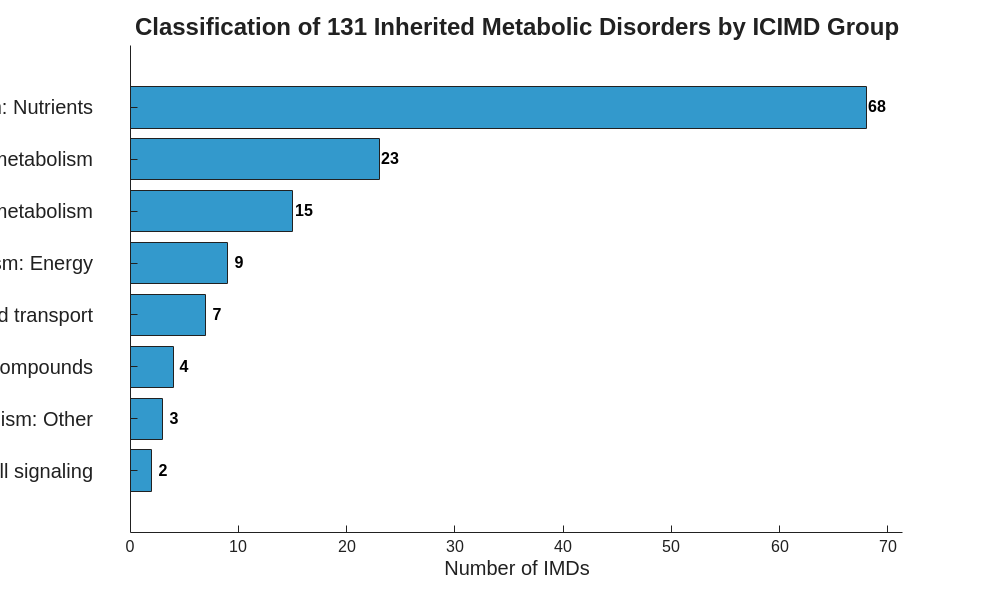

% Load IMD data
IMDList = readtable(fullfile(dataFolder, 'IMD_List.xlsx'));

% Sample cell array
cellArray = IMDList.ICIMDGroup;

IEMbaseNosologyCodes = IMDList.IEMbaseNosologyCode;

% Find unique strings and their counts
[uniqueStrings, ~, idx] = unique(cellArray);
counts = accumarray(idx, 1);

% Sort the data in descending order
[countsSorted, sortIdx] = sort(counts, 'ascend');
uniqueStringsSorted = uniqueStrings(sortIdx);

% Create the bar chart
fig = figure('Color', 'w'); % Set figure background to white

figHeight = max(600, 25 * numel(uniqueStringsSorted)); % ~25 pixels per bar
fig.Position = [100, 100, 1000, figHeight];

b = barh(countsSorted, 'FaceColor', [0.2, 0.6, 0.8]); % Create horizontal bar chart

% Customize the axes and labels
% Hide Y-axis tick labels
set(gca, 'YTickLabel', []);

% Plot them manually with offset
yPositions = 1:numel(uniqueStringsSorted);
xOffset = -0.05 * max(countsSorted);  % Adjust this value as needed for spacing
set(groot, 'defaultTextFontName', 'Arial');

set(gca, 'FontName', 'Arial', 'FontSize', 12);
for i = 1:numel(yPositions)
    text(xOffset, yPositions(i), uniqueStringsSorted{i}, ...
        'HorizontalAlignment', 'right', ...
        'VerticalAlignment', 'middle', ...
        'FontSize', 15, ...
        'Interpreter', 'none'); % Prevent TeX interpretation
end

xlabel('Number of IMDs', 'FontSize', 15);


% Adjust the x-axis limit to be a couple of units more than the longest bar
xlim([0 max(countsSorted) + 0.05*max(countsSorted)]);

% Add the counts as text labels at the end of each bar
xPos = countsSorted; % X positions for text labels
yPos = 1:numel(countsSorted); % Y positions for text labels
text(xPos+0.2, yPos, num2str(xPos), 'vert', 'middle', 'horiz', 'left', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');



% Remove the box outline for a cleaner look
box off;

% Set the figure's PaperPositionMode and PaperSize
set(fig, 'PaperPositionMode', 'auto');
set(fig, 'PaperUnits', 'inches');
set(fig, 'PaperSize', [12, 15]);
set(fig, 'PaperPosition', [0, 0, 12, 15]);

t = title(sprintf('%s%d%s','Classification of ', numel(IEMbaseNosologyCodes), ' Inherited Metabolic Disorders by ICIMD Group'), 'FontSize', 18);

exportgraphics(fig, fullfile(graphicFolder, 'IMD_ICIMD_Group.eps'), ...
    'ContentType', 'vector', 'BackgroundColor', 'none');

## Calculate Distribution of Diagnostic Confidence Score (DCS) Across All Inherited Metabolic Diseases

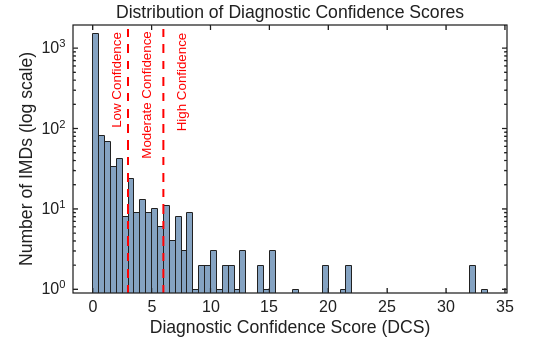

% Calculate Diagnostic Confidence Score
[DCSnum] = calDCS();

% Create a histogram and store the bin counts
figure;
h = histogram(DCSnum, 'BinWidth', 0.5, 'FaceColor', [0.2 0.4 0.6]);
hold on;

% Set y-axis to logarithmic scale
set(gca, 'YScale', 'log');

% Compute 10% margin above the tallest bar
maxCount = max(h.Values);
yMax = 10^(log10(maxCount) + 0.1); % approx 1.26 × maxCount = +10% in log space
ylim([0.9, yMax]); % start slightly above zero for log scale visibility

% Overlay threshold lines at 3 and 6
plot([3 3], [0.9 yMax], 'r--', 'LineWidth', 1.5);
plot([6 6], [0.9 yMax], 'r--', 'LineWidth', 1.5);

% Add vertically rotated text labels at log-midpoint
labelY = sqrt(0.9 * yMax);
text(2.0, 400, 'Low Confidence', ...
    'Color', 'r', 'FontSize', 10, 'HorizontalAlignment', 'center', 'Rotation', 90);
text(4.5, 260, 'Moderate Confidence', ...
    'Color', 'r', 'FontSize', 10, 'HorizontalAlignment', 'center', 'Rotation', 90);
text(7.5, 380, 'High Confidence', ...
    'Color', 'r', 'FontSize', 10, 'HorizontalAlignment', 'center', 'Rotation', 90);

% Annotate plot
xlabel('Diagnostic Confidence Score (DCS)');
ylabel('Number of IMDs (log scale)');
title('Distribution of Diagnostic Confidence Scores', 'FontWeight', 'normal');
grid off;
hold off;

% Save figure
exportgraphics(gcf, fullfile(graphicFolder, 'DCS_distribution.png'), 'Resolution', 600);
exportgraphics(gcf, fullfile(graphicFolder, 'DCS_distribution.eps'), 'ContentType', 'vector');

## Recruitment and participation rate visualisation

% generateBarFig.m
% Publication-ready EPS with Arial if available.
% Outputs in ./figures:
%   reasons_no_inclusion_bar.eps
%   reasons_no_inclusion_pareto.eps

%% Font selection
fonts = listfonts;
if any(strcmpi(fonts, 'Arial'))
    fontname = 'Arial';
else
    fontname = 'Helvetica'; % fallback
    warning('Arial not found. Install Microsoft core fonts if you need strict Arial.');
end

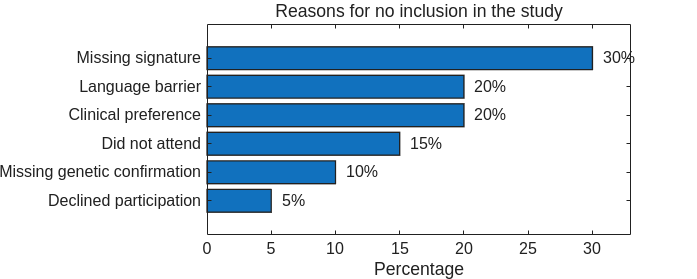


set(groot, 'DefaultAxesFontName', fontname, ...
                 'DefaultTextFontName', fontname, ...
                 'DefaultAxesFontSize', 12, ...
                 'DefaultTextInterpreter', 'none', ...
                 'DefaultAxesLineWidth', 1.0, ...
                 'DefaultAxesTickDir', 'in', ...
                 'DefaultAxesBox', 'off');

%% Data (short labels, with manual line breaks where useful)
reasons = { ...
    'Missing signature', ...
    'Language barrier', ...
    'Clinical preference', ...
    'Did not attend', ...
    'Missing genetic confirmation', ...
    'Declined participation' ...
    };
pct = [30 20 20 15 10 5];

% Sort by percentage descending
[pctSorted, idx] = sort(pct, 'descend');
reasonsSorted = reasons(idx);

%% 1) Horizontal bar chart (wider)
fig1 = figure('Units','inches', ...
              'Position',[0.5 0.5 9.5 3.8], ...   % width=9.5in, height=3.8in
              'Color','w', ...
              'Renderer','painters');             % vector output

y = 1:numel(pctSorted);
barh(y, pctSorted, 'LineWidth', 1);
set(gca, 'YTick', y, 'YTickLabel', reasonsSorted, 'YDir', 'reverse', 'Layer', 'top');

xlim([0 33]);                 % give a little more headroom to the right
xticks(0:5:35);
xlabel('Percentage');

% Annotate percentages, keep inside the axes with a small margin
for i = 1:numel(pctSorted)
    xtext = min(pctSorted(i) + 0.8, 39);   % avoid clipping at the right edge
    text(xtext, y(i), sprintf('%d%%', pctSorted(i)), ...
        'VerticalAlignment', 'middle', 'HorizontalAlignment', 'left','FontSize',12);
end

title('Reasons for no inclusion in the study','FontWeight','normal','FontSize',18);

% Make the printed EPS match on-screen size
set(fig1, 'PaperUnits','inches', 'PaperPosition', get(fig1,'Position'));
print(fig1, fullfile(graphicFolder, 'reasons_no_inclusion_bar.eps'), '-depsc', '-vector');

## Disease Prevalence and Recruitment Model 

Let $\( \mathbf{D} \in \mathbb{N}^{m \times n} \)
$ be a *disease prevalence matrix*, where $\( D_{i,j} \)$ is the number of patients of IMD $\( i \)$ under observation  at hospital $\( j \)$. Let $\( X \in \mathbb{R}^{m \times n} \)$ be a *recruitment fraction matrix*, where $\( X_{i,j} \)$ is the fraction of patients of IMD $\( i \)$ recruited at HCP $\( j \)$. Let $\( Y \in \mathbb{R}^{m \times n} \)$ be a *recruitment number matrix*, where $\( Y_{i,j} \)$ is the number of patients of IMD $\(i\)$ recruited at HCP $\( j \)$. Assume that $\( \mathbf{D }\)$ is constant while $\( X \)$ and $\( Y \)$ are variables. Then we have:


$$\[\mathbf{D} \circ X = Y,\]$$


where $\( \circ \)$ denotes the Hadamard product, that is,  $\( \mathbf{D}_{i,j} \times X_{i,j} = Y_{i,j} \).$

In orther to optimise this patient allocation problem so that each IMD would be centered at each hospital as much as possible, the following cardinality optimisation would be solved:


$$\[\text{min} \quad \left\Vert X\right\Vert _{0}
\]

$$



$$% Subject to:
\[
D \circ X - Y = 0, 
\]
$$



$$
\[
0 \leq X_{i,j} \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]$$


where $m
$ and $n
$ represent number of IMDs and hospitals respectively.

Lets make a random example for  *disease prevalence matrix:* 

% Load IMD vs HCP matrix (number of patients per IMD at each HCP)
% patientsData = readtable("PatinetsPerHCP.xlsx");
patientsData = readtable(fullfile(dataFolder, "PatinetsPerHCP_noised.xlsx"));

% extract numeric part of the matrix
id = find(ismember(patientsData.Properties.VariableNames, 'HCP_1'));
HCPname = patientsData.Properties.VariableNames(id:end)';

D = patientsData(:, end-23:end);
D = table2array(D);
% D = anonymiseData(D, epsilon);
% patientsData_noised = patientsData;

[m, n] = size(D);
fprintf('%s%d\n', 'Number of IMDs: ', m);

Number of IMDs: 131


fprintf('%s%d\n', 'Number of hospitals: ', n);

Number of hospitals: 24


## Mathematical Vectorising Checking

When constructing a mathematical problem as input for optimisation, one must keep in mind that applying functions directly to decision variables is often infeasible, as it complicates the optimisation process. However, we can reformulate known variables and construct the left-hand side (LHS) matrix accordingly. Therefore, here we (i) vectorise each decision variable and (ii) transform mathematical functions involving these variables into a matrix-vector linear algebraic product, enabling the use of linear optimisation techniques.

By converting the matrix-matrix Hadamard product to matrix-vector product (magnus et.al. 1985), above equation can be converted into:


$$\[\text{min} \quad \left\Vert \text{vec} (X)\right\Vert _{0}
\]
$$



$$\[\text{s.t:}\]
\[
\text{diag(vec}(D)) \cdot \text{vec}(X) = \text{vec}(Y),
\]
$$



$$\[
0 \leq \text{vec}(X_{i,j}) \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]
$$


where the $\mathrm{vec}$ function vectorises a matrix into a column vector by stacking its columns into a single column, and $\mathrm{diag}$ function generates a square diagonal matrix where the elements of the vector become the diagonal entries of the matrix,

and all off-diagonal entries are zero. As a result, this reformulation turns the matrix of variables $X$ into decision variable vector $\mathrm{vec}(X)$, and the right hand-side matrix $Y$ to the right hand-side vector $\mathrm{vec}(Y)$, while keeping the element-wise characteristics of the Hadamard product. First we check the validity of this optimisation conversion by defining an arbitrary $X$ matrix: 

% Define X
% Define a sparse matrix
density = 0.6;
% Generate random values between 0 to 1
values = rand(1, numel(find(D)));
[rowIndices, colIndices] = ind2sub([m, n], find(D));

X = sparse(rowIndices, colIndices, values', m, n);

% Define Y:
Y = D .* X;

% Define vec(D)
vec_D = D(:);
diag_vec_D = diag(vec_D);

% Define vec(X):
vec_X = X(:);

% Define vec(Y);
vec_Y = Y(:);

% Now test the mathematics:
assert(all(diag_vec_D * vec_X == Y(:)));
fprintf('%s','Mathematical testing passed!')

Mathematical testing passed!

Now we can turn this table and the problem into a coding compatible problem:

% Defining the left hand-side matrix (LHS):
LHS = [diag_vec_D, -speye(m*n)];

% Test the correctness of LHS definition:
% We should have LHS * [vec(X); vec(Y)] = 0;
assert(all(LHS * [vec_X; vec_Y] == 0));

% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality ||vec(X)||_0
problem.p = zeros((m*n)+(m*n), 1);
% X
problem.p(1:(m*n)) = true;

% Define q vector for one-norm cardinality ||vec(Y)||_1
problem.q = zeros((m*n)+(m*n), 1);

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = sparse((m*n)+(m*n), 1);
ub = sparse((m*n)+(m*n), 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% Define csense
csense = [repmat('E', m*n, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;
solverOk = changeCobraSolver('gurobi', 'All');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > changeCobraSolver: Solver for MIQP problems has been set to gurobi.
 > changeCobraSolver: Solver gurobi not supported for problems of type CLP. No solver set for this problemtype 
 > changeCobraSolver: Solver gurobi not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver gurobi not supported for problems of type NLP. No solver set for this problemtype 


solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

3144 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

0 max cardinality variables:
         NaN mean(c(q))	         NaN min(c(q))	         NaN max(c(q))
           1 delta0	         NaN min(d)	         NaN max(d)
       1e-06 delta1	         NaN min(o(q))	         NaN max(o(q))

3144 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50           0           0           0           0           0           0           0          -0          -0           0         NaN           0  

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 6288


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 3144


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 0


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 6288


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 3144


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 3144


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0607 seconds


As we were trying to minimise zero cardinality of number of patients with no constraints, cardinality optimisation would asign every variable to **zero**!  whereas in real-world problems there are constraints as for example a minimum number of patients is required to construct a valid clinical study, that is why zero number of patients is not acceptable! 

In the next step such constraints are included.

## Add constraints to number of patients per hospital and number of patients per disease

In most cases each hospital has a maximum capacity for recruiting patients according to its facilities and human resources. Also in studies with more than one disease involved, one need to make sure to include a proper number of patients per disease inorder to construct a reliable clinical study.

In this case the mathematical problem would be reformulated as follows


$$\[\text{min} \quad \left\Vert (X)\right\Vert _{0}
\]
$$



$$
\[\text{s.t:}\]

\[
D \circ X - Y = 0
\]


$$



$$\[
Y * \mathbf{1}_n - y = 0
\]
$$



$$\[
Y^T * \mathbf{1}_m - z = 0
\]
$$



$$\[
0 \leq X_{i,j} \leq 1, \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots n
\]
$$



$$\[
lb_{y_i} \leq y_i \leq ub_{y_i}
\]
\[
lb_{z_j} \leq z_j \leq ub_{z_j}
\]
$$


where *number of patients recruited per IMD* is $\[
y := Y \cdot \mathbf{1} \in \mathbb{R}^{m \times 1}
\]$, and the *number of patients recruited per HCP* is $\[
z := Y^T \cdot \mathbf{1} \in \mathbb{R}^{n \times 1}
\]$, where $\mathbf{1}$ denotes a vector of ones of appropriate dimension.


$$\[
\mathrm{vec}(ABC) = (C^{T} \otimes A) \cdot \mathrm{vec}(B)
\]

$$



$$\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = y
\]$$



$$
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathrm{vec}(Y^{T}) = z
\]$$



$$\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]$$



$$\[
\mathbf{K}_{mn} \cdot \mathrm{vec}(M) = \mathrm{vec}(M^{T})
\]$$



$$% Derivation of the commutation matrix:
\[
\mathbf{K}_{mn} = \sum_{i=1}^{m} \sum_{j=1}^{n} (\mathbf{E}_{ij} \otimes \mathbf{E}_{ji})
\]
$$


We can benchmark the validity of the first two equations as follows:

assert(all(kron(ones(n, 1)', eye(m)) * Y(:) == sum(Y, 2)))
fprintf('%s', 'Conversion formula for y equation is correct!')

Conversion formula for y equation is correct!

tY = Y';
assert(all(kron(ones(m, 1)', eye(n)) * tY(:) == sum(Y, 1)'))
fprintf('%s', 'Conversion formula for z equation is correct!')

Conversion formula for z equation is correct!

Then the commutation matrix $% Derivation of the commutation matrix:
\[
\mathbf{K}_{mn} 
\]
$ can be coded as follows:

% Generate all combinations of row indices i and column indices j
[I, J] = ndgrid(1:m, 1:n);

% Compute the position indices in vec(A') and vec(A)
p = n * (I(:) - 1) + J(:);  % Indices in vec(A')
q = m * (J(:) - 1) + I(:);  % Indices in vec(A)

% Create the sparse commutation matrix
Kmn = sparse(p, q, ones(m * n, 1), m * n, m * n);

Then the functionality of commutation matrix can be tested as follows:

assert(all(kron(ones(m, 1)', eye(n)) * Kmn * Y(:) == sum(Y, 1)'))
fprintf('%s', 'The commutation matrix is functioning correctly!')

The commutation matrix is functioning correctly!

Now we are able to construct the problem and solve it:

% Defining the left hand-side matrix (LHS):
P_y = kron(ones(n, 1)', eye(m));
P_z = kron(ones(m, 1)', eye(n)) * Kmn;

% Variables   vec(X) (m*n)           vec(Y)  (m*n)        y (m*1)                z (n*1)
LHS =        [diag_vec_D   ,         -speye(m*n),         zeros(m*n, m),         zeros(m*n, n);...
    zeros(m, m*n),         P_y        ,         -speye(m)    ,         zeros(m, n)  ;...
    zeros(n, m*n),         P_z        ,         zeros(n, m)  ,         -speye(n)        ];

% Test the correctness of LHS definition:
% We should have LHS * [vec(X); vec(Y)] = 0;
assert(all(LHS * [vec_X; vec_Y; sum(Y, 2); sum(Y, 1)'] == 0));
fprintf('%s', 'Left hand-side matrix is built correctly')

Left hand-side matrix is built correctly

## Extract the number of patients determined based on Diagnostic Confidence Score

nn = numel(IEMbaseNosologyCodes);
patientNumberLB = zeros(nn, 1);
patientNumberUB = zeros(nn, 1);

for i = 1:nn
    parts = split(IMDList.DCSPatientNumber{i}, '-');
    patientNumberLB(i) = str2double(strtrim(parts{1}));
    patientNumberUB(i) = str2double(strtrim(parts{2}));
end

% upper and lower bound on number of patients per IMD (y)
maxPatientsPerIMD = sum(D, 2);
id = maxPatientsPerIMD < patientNumberLB;
patientNumberLB(id) = maxPatientsPerIMD(id);

## Set maximum number of patients per health care provider

% For most of the hospitals this values is 40 patients
HCPpatientNumberUB = 40 * ones(numel(HCPname), 1);
% For leading hospitals a maximum of 265 patients is set
% HCP_20, HCP_18, HCP_2
leadingID = ismember(HCPname, {'HCP_20', 'HCP_18', 'HCP_2'});
HCPpatientNumberUB(leadingID) = 265;

### Implementation of the overal problem

After confirming the conversion of optimisation problem, the overal problem would be as follows:


$$\[\text{min} \quad \left\Vert \text{vec} (X)\right\Vert _{0}
\]
$$



$$\[\text{s.t:}\]
\[
\text{diag(vec}(D)) \cdot \text{vec}(X) = \text{vec}(Y),
\]
$$



$$\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = y
\]$$



$$\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]$$



$$
\[
0 \leq \text{vec}(X_{i,j}) \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]
$$



$$\[
lb_{y_i} \leq y_i \leq ub_{y_i}
\]
\[
lb_{z_j} \leq z_j \leq ub_{z_j}
\]
$$


In this section, above problem is coded and tried to be solved by Cardinality optimisation problem:

clear problem
% Variables   vec(X) (m*n)           vec(Y)  (m*n)        y (m*1)                z (n*1)
LHS =        [diag_vec_D   ,         -speye(m*n),         zeros(m*n, m),         zeros(m*n, n);...
    zeros(m, m*n),         P_y        ,         -speye(m)    ,         zeros(m, n)  ;...
    zeros(n, m*n),         P_z        ,         zeros(n, m)  ,         -speye(n)        ];

% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality ||vec(X)||_0
variableSize = (m*n) + (m*n) + m + n;
problem.p = zeros(variableSize, 1);
problem.p(1:(m*n)) = true;

% Define q vector for one-norm cardinality
problem.q = zeros(variableSize, 1);

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = sparse(variableSize, 1);
% Relax the upper bound
ub = 10000 + sparse(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% open the upper bound for Y variable
ub(m*n+1:m*n + m*n) = 10000;

% Set number of patients to numbers calculated by Diagnostic Confidence Score
lb(m*n+m*n+1: m*n+m*n+m) = 0.7 * patientNumberLB;
ub(m*n+m*n+1: m*n+m*n+m) = patientNumberUB;

% Set number of patients per hospital to the half possible value
% lb(m*n+m*n+m+1: m*n+m*n+m+n) = 0;
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Define csense
csense = [repmat('E', m*n+m+n, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;
solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

3144 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

0 max cardinality variables:
         NaN mean(c(q))	         NaN min(c(q))	         NaN max(c(q))
           1 delta0	         NaN min(d)	         NaN max(d)
       1e-06 delta1	         NaN min(o(q))	         NaN max(o(q))

3299 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  3.2018e+05     1.7e+02     1.7e+02           0         414     1.7e+02     0.00034          -0          -0           0         NaN           0  

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X = solution.xyz(1:m*n);
X = reshape(X, m, n);

% Y
Y = solution.xyz(m*n+1: 2*m*n);
Y = reshape(Y, m, n);

% y
y = solution.xyz(2*m*n+1:2*m*n+m);
y = reshape(y, m, 1);

% z
z = solution.xyz(2*m*n+m+1:end);
z = reshape(z, n, 1);

% Define a threshold
tol = 1e-6;

% Test the results
assert(all(all(D.*X - Y < 1e-6)));
assert(all(Y*ones(n, 1) - y < tol));
assert(all(Y'*ones(m, 1)- z < tol));

% Test the constraints
assert(all(all(X >= 0)));
assert(all(all(X - 1 < tol)));
% assert(all(y >= patientNumberLB));
% assert(all(y <= patientNumberUB));
% assert(all(z >= lb_z));
% assert(all(z <= ub_z));

% Output a success message
fprintf('Calculations are correct!')

Calculations are correct!

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 6443


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 3299


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 0


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 3430


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 3144


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 3144


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0369 seconds


In real-world, we aim to recruit patients for as many IMDs as possible. This goal lead to intorduction of maximum one norm carinality of number of patients per IMD. Therefore the overal problem would be presented as follows:


$$\[\text{min} \quad \left\Vert \text{vec} (X)\right\Vert _{0}-\left\Vert y\right\Vert _{1}
\]
$$



$$\[\text{s.t:}\]
\[
\text{diag(vec}(D)) \cdot \text{vec}(X) = \text{vec}(Y),
\]
$$



$$\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = y
\]$$



$$\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]$$



$$
\[
0 \leq \text{vec}(X_{i,j}) \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]
$$



$$\[
lb_{y_i} \leq y_i \leq ub_{y_i}
\]
\[
lb_{z_j} \leq z_j \leq ub_{z_j}
\]
$$


% Define q vector for one-norm cardinality ||vec(Y)||_1
problem.q(2*m*n+1:2*m*n+m) = true;
problem.r(2*m*n+1:2*m*n+m) = false;

% Set the coeeficients
problem.delta0 = 0;         % global parameter on maximise `||y||_0`
problem.delta1 = -1;        % global parameter on minimise `||y||_1
solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

3144 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

131 max cardinality variables:
           0 mean(c(q))	           0 min(c(q))	           0 max(c(q))
           0 delta0	           0 min(d)	           0 max(d)
          -1 delta1	           1 min(o(q))	           1 max(o(q))

3168 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  3.2272e+05     5.3e+02    -1.2e+03           0         516     2.3e+02     0.00045          -0          -0    -1.4e+03         NaN           0

y2 = solution.xyz(2*m*n+1:2*m*n+m);
y2 = reshape(y2, m, 1);
% Adding mazimum one norm to the objective function must increase y value
assert(all(y2 >= y), 'Number of patients per IMD did not increase');

fprintf('New objective function leads to increase in number of patients per IMD!')

New objective function leads to increase in number of patients per IMD!

## Optimisation of sample allocation to analytical labs 

Let $\mathbf{T}\in\{0,1\}{}^{p\times q}$ be a *targeted platform matrix, *where $\mathbf{T}_{i,j}=1$ if metabolite $i$ is measured by metabolomic platform $j$ and $\mathbf{T}_{i,j}=0
$ otherwise. Let $U\in\mathbb{R}^{q\times m}$ be a *targeted platform utilisation matrix* where $U_{i,j}$ is the number of times that targeted platform $i$ is assigned to measure a sample from a patient with IMD $j$. Let $S\in\mathbb{R}^{p\times m}$ be a *analytical measurement matrix*, where $S_{i,j}$ is the number of times that metabolite $i$ is assigned to be measured in all sample from a patient with IMD $j$ across all targeted platforms. Assume that $\mathbf{T}
$ is constant while $U$ and $S$ are variables. Then we have


$$\mathbf{T}\cdot U=2S,
$$


Notably, coefficient 2 is added to the right side of the equation as both urine and plasma sample are collected in Recon4IMD, therefore there is two samples assigned to each patient. Same as targeted platform selection, a cardinality optimisation applies to global platforms. Let $\mathbf{G}\in\{0,1\}{}^{p\times z}$ be a *global platform matrix* where $\mathbf{G}_{i,j}=1$ if metabolite $i$ is measured by global metabolomic platform $j$ and $\mathbf{G}_{i,j}=0$ otherwise. Let

$H\in\mathbb{R}^{z\times m}$ be a global *platform utilisation matrix* where $H_{i,j}$ is the number of times that global platform $i$ is assigned to measure a sample from a patient with IMD $j$. As we aim to screen every known metabolite biomarker with both targeted and global metabolomic platform, the *measurement matrix* (S) is the same for both global and targeted platforms, therefore:


$$\mathbf{G}\cdot H=2S,$$


We assume that the same set of platforms are chosen for each patient with the same IMD, but different combinations of platforms may be used for different IMDs. Minimisation of the number of different platforms required to measure all biomarkers for each IMD may be represented as the cardinality optimisation problem


$$\[
\underset{U, H, S}{\text{min}} \quad \| U \|_0+\| H \|_0
\]
\[
\text{s.t.} \quad \mathbf{T} \cdot U = 2S,
\]

\[
\quad \quad \mathbf{G} \cdot H = 2S,
\]
$$


Convert matrix-matrix multiplication to matrix-vector multiplication to incorporate mathematical optimisation:


$$\[
\underset{U, H, S}{\text{min}} \quad \| \text{vec}(U) \|_0 + \| \text{vec}(H) \|_0
\]
\[\text{s.t.} \quad
(\mathbf{I_{m}} \otimes \mathbf{T}) \cdot \mathrm{vec}(U) = 2\mathrm{vec}(S),
\]
\[
\quad \quad(\mathbf{I_{m}} \otimes \mathbf{G}) \cdot \mathrm{vec}(H) = 2\mathrm{vec}(S).
\]$$


## Discrete sample types

superSheet = readtable('data/IMD_mapped.xlsx', 'Sheet', 'superSheet2', 'ReadVariableNames', true, 'ReadRowNames',false);
% Identify rows that need to be split
multiSampleRows = contains(superSheet.SampleType, 'Plasma, Urine');

% Extract the rows that need duplication
rowsToDuplicate = superSheet(multiSampleRows, :);

% Modify the duplicated rows for Plasma
plasmaRows = rowsToDuplicate;
plasmaRows.SampleType(1:end) = {'Plasma'};

% Modify the duplicated rows for Urine
urineRows = rowsToDuplicate;
urineRows.SampleType(1:end) = {'Urine'};

% Remove the original rows that had 'Plasma, Urine'
superSheet(multiSampleRows, :) = [];

% Append the newly created rows to the table
superSheet = [superSheet; plasmaRows; urineRows];

% Sort the table by the first column (assuming it's named correctly)
firstColumnName = superSheet.Properties.VariableNames{1}; % Get the first column name dynamically
superSheet = sortrows(superSheet, firstColumnName); % Sort by the first column

% Add one column to the super Sheet that represents metabolite+sample type
superSheet.metSampleType = arrayfun(@(x) strcat(superSheet.MetaboliteName{x}, '_', superSheet.SampleType{x}), (1:numel(superSheet.MetaboliteName))', 'UniformOutput', false);



## Load targeted platforms costs

% Targeted platforms and T matrix
aminoAcids = contains(lower(superSheet.TestPanelGroup), 'amino acids');                   % Define Amino acids
vlcfa = contains(lower(superSheet.TestPanelGroup), 'very-long-chain fatty acids');        % Define VLCFA test panel
purines = contains(lower(superSheet.TestPanelGroup), 'purines and pyrimidines');          % Define purine and pyrimidines
polyols = contains(lower(superSheet.TestPanelGroup), 'polyols');                          % Define polyols
organicAcids = contains(lower(superSheet.TestPanelGroup), 'organic acids');               % Define organic acids
acylcarnitines = contains(lower(superSheet.TestPanelGroup), 'acylcarnitines');            % Define acylcarnitines
oligosaccharides = contains(lower(superSheet.TestPanelGroup), 'oligosaccharides');        % Define Oligosaccharides


emptyIdx = cellfun(@isempty, superSheet.SampleType);                                      % Also include empty sample types
urine = contains(lower(superSheet.SampleType), 'urine') | emptyIdx;                       % Define urine sample type
plasma = contains(lower(superSheet.SampleType), 'plasma') | emptyIdx;                     % Define plasma sample type

% Filter metabolite biomarkers based on multiple conditions
wrongSampleType = ismember(superSheet.SampleType, {'blood', 'Dried Blood Spot', 'Blood'});
superSheet.recon4IMDsampleType(wrongSampleType) = 0;
recruitableMetIndex = ismember(superSheet.IEMNosologyCode, IEMbaseNosologyCodes);
recruitableMetIndex = recruitableMetIndex .* superSheet.recon4IMDsampleType .*  superSheet.anyTargetedPlatform .* superSheet.modellable .* superSheet.icimdGene;
recruitableMetIndex = logical(recruitableMetIndex);

% Remove functional biomarkers
functionalBio = contains(superSheet.TestPanel, 'Functional testing');
finalIEMbase2 = unique(superSheet.IEMNosologyCode(~functionalBio & recruitableMetIndex), 'stable');
assert(isequal(sort(IEMbaseNosologyCodes), sort(finalIEMbase2)));
disp('Removing functional testing metabolites is not deleting any IMD');

Removing functional testing metabolites is not deleting any IMD


recruitableMetIndex = recruitableMetIndex & ~functionalBio;

finalMetBiomarker = superSheet.metSampleType(recruitableMetIndex);
% [finalMetBiomarkerName, uniqueID] = unique(finalMetBiomarker, 'stable');
% 
% T = T(recruitableMetIndex, :);
% T = table2array(T(uniqueID, :));
% % Check the T matrix, every metabolite should be measured by at least one targted platform
% assert(all(sum(T, 2)))

[finalMetBiomarkerName, uniqueMetID] = unique(finalMetBiomarker, 'stable');

targetedLabels = {'Lab1', 'Lab2', 'Lab3', 'Lab4', 'Lab5', 'Lab6'};

targetedColumns = strcat(targetedLabels, 'Targeted');
[~, targetedColumnsID] = ismember(targetedColumns, fieldnames(superSheet));
T = superSheet(recruitableMetIndex, targetedColumnsID);
T = table2array(T(uniqueMetID, :));
% Check the T matrix, every metabolite should be measured by at least one targted platform
assert(all(sum(T, 2)))

## Global platforms and their cost and G matrix

%finalMetBiomarker = superSheet.MetaboliteName(recruitableMetIndex);
finalMetBiomarker = superSheet.metSampleType(recruitableMetIndex);
[finalMetBiomarkerName, uniqueMetID] = unique(finalMetBiomarker, 'stable');

globalColumns = superSheet.Properties.VariableNames(contains(superSheet.Properties.VariableNames, 'Global'));
removeID = ismember(globalColumns, 'anyGlobalPlatform');
globalColumns(removeID) = [];


[~, globalColumnsID] = ismember(globalColumns, fieldnames(superSheet));
G = superSheet(recruitableMetIndex, globalColumnsID);
G = table2array(G(uniqueMetID, :));

% find empty rows fix later
% emptyRows = sum(G, 2) == 0;
% G(emptyRows, end) = 1;

% Check the G matrix, every metabolite should be measured by at least one global platform
assert(all(sum(G, 2)))
assert(all(sum(G, 1)))

## Build B matrix

% Extract unique metabolite names
finalMetBiomarker = superSheet.metSampleType(recruitableMetIndex);
[finalMetBiomarkerName, ~, idxUnique] = unique(finalMetBiomarker, 'stable');

% Initialize binary association matrix
numMet = numel(finalMetBiomarkerName);
numIMD = numel(IEMbaseNosologyCodes);
Met2IMD = false(numMet, numIMD);

% Populate Met2IMD using vectorized operations
for i = 1:numIMD
    IEMid = ismember(superSheet.IEMNosologyCode, finalIEMbase2(i));
    % meti = superSheet.MetaboliteName(IEMid & recruitableMetIndex);
    meti = superSheet.metSampleType(IEMid & recruitableMetIndex);
    [matched, ~] = ismember(finalMetBiomarkerName, meti);
    Met2IMD(matched, i) = true;
end

% Validate constraints
assert(all(sum(Met2IMD, 1)), 'Each IMD must have at least one metabolite biomarker.');
assert(all(sum(Met2IMD, 2)), 'Each metabolite biomarker must be assigned to at least one IMD.');

% Output result
B = Met2IMD;

%% extract a subset out of the super sheet
subSuperSheet = superSheet(recruitableMetIndex, :);% Generate a random number for number of metabolite biomarkers
[p, q] = size(T);

% Generate a random number for number of global platforms
[p, w] = size(G);

% Set a density for number of non zero elements
density = 0.4;

% Make a random targeted platform matrix
% Generate random row and column indices for non-zero elements
numNonZeros = round(density * p * q); % Total number of non-zero elements

% Generate all possible linear indices
allIndices = 1:(p * q); % This creates a list of all linear indices in the m x n matrix

% Randomly select k unique linear indices
randomIndices = randperm(p * q, numNonZeros); % Randomly select k unique indices from allIndices

% Convert linear indices to (i, j) subscripts
[rowIndices, colIndices] = ind2sub([p, q], randomIndices);

% Random values between 1 and 10 patients
values = randi([1, 1], numNonZeros, 1);

% Create a random targeted platform utilisation matrix U
% Randomly select k unique linear indices
randomIndices = randperm(q * m, numNonZeros);

% Convert linear indices to (i, j) subscripts
[rowIndices, colIndices] = ind2sub([q, m], randomIndices);
values = randi([1, 10], numNonZeros, 1);
U = sparse(rowIndices, colIndices, values, q, m);

% Calculate S matrix to ensure that mathematical conversions are working
% well
S = 0.5 * T * U;

assert(all(kron(speye(m), T) * U(:) == 2*S(:)));
fprintf('Mathematical conversion for targeted platforms is correct');

Mathematical conversion for targeted platforms is correct


%% Make the same for global platforms
% Generate random row and column indices for non-zero elements
numNonZeros = round(density * p * w); % Total number of non-zero elements

% Generate all possible linear indices
allIndices = 1:(p * w); % This creates a list of all linear indices in the m x n matrix

% Randomly select k unique linear indices
randomIndices = randperm(p * w, numNonZeros); % Randomly select k unique indices from allIndices

% Convert linear indices to (i, j) subscripts
[rowIndices, colIndices] = ind2sub([p, w], randomIndices);

% True values
values = ones(numNonZeros, 1);

% Create a random targeted platform utilisation matrix U
% Randomly select k unique linear indices
randomIndices = randperm(w * m, numNonZeros);

% Convert linear indices to (i, j) subscripts
[rowIndices, colIndices] = ind2sub([w, m], randomIndices);
values = randi([1, 10], numNonZeros, 1);
H = sparse(rowIndices, colIndices, values, w, m);

% Calculate S matrix to ensure that mathematical conversions are working
% well
S = 0.5 * G * H;

assert(all(kron(speye(m), G) * H(:) == 2*S(:)));
fprintf('Mathematical conversion for global platforms is correct');

Mathematical conversion for global platforms is correct

Having ensured that the conversions are set correctly, we can now proceed to code the optimisation problem.


$$\[
\underset{U, H, S}{\text{min}} \quad \| \text{vec}(U) \|_0 + \| \text{vec}(H) \|_0
\]
\[\text{s.t.} \quad
(\mathbf{I}_{m} \otimes \mathbf{T}) \cdot \mathrm{vec}(U) = 2\mathrm{vec}(S),
\]
\[
\quad \quad(\mathbf{I}_{m} \otimes \mathbf{G}) \cdot \mathrm{vec}(H) = 2\mathrm{vec}(S).
\]$$


% For the feasibility in this example T = G, and U = H, and z = q;
T1 = G;
U1 = H;
q1 = w;

% Define the left hand side matrix
% variables:
%    vec(U)                        vec(H)                           vec(S)
LHS = [...
    kron(speye(m), T1)  ,          sparse((p*m),(w*m)),             -2*speye(p*m);...
    sparse((p*m),(m*q1)),          kron(speye(m), G)  ,             -2*speye(p*m)];

% test to see if the left hand side matrix is set correctly
assert(all(LHS*[U1(:); H(:); S(:)] == 0));
fprintf('Left hand-side matrix is defined correct!');

Left hand-side matrix is defined correct!

## 2.3** Integration of patient recruitment and sample allocation**

Samples will be collected from diagnosed patients and every sample undergoes both targeted and global metabolomic analysis. Therefore, to mathematically connect two problems, one must consider that every sample that is collected must be analysed in a lab. Since samples belong to different IMDs, researchers look for different metabolite biomarker in each sample, the correlation between and IMD and its known metabolite biomarkers are retrieved from IEMbase database and clinical literature. Collecting such data results in definition of a *biomarker matrix* $\mathbf{B}\in\{0,1\}{}^{p\times m}$, where $\mathbf{B}_{i,j}=1$ if metabolite $i$ is a biomarker of IMD $j$ and $\mathbf{B}_{i,j}=0$ otherwise. By multipling number of patients per IMD and vector of metabolite biomarkers of that IMD, one can determine number of times that each metabolite should be screened as a biomarker for each IMD:


$$\[
\mathbf{B}(y) := \mathbf{B} \cdot \text{diag}\left(y\right) \in \mathbb{R}^{p \times m},
\]
$$


therefore, $\mathbf{B}_{i,j}(y)$ is the number of times that metabolite $i$ is required to be measured as a biomarker for IMD $j$. Therefo both variables of $\mathbf{B}_{i,j}(y)$ and $S$ represent the same property. Hence one can conclude that:


$$\[
\mathbf{B} \cdot \text{diag}\left(y\right) = S,
\]
$$


meaning that every possible sampled metabolite biomarker is analysed by metabolomic labs. As previous equations restricts the problem, they are relaxed to ensure a feasible solution:


$$
\[
\mathbf{T} \cdot U \geq 2S
\]
\[
\mathbf{G} \cdot H \geq 2S
\]
$$


This relaxation implies that every metabolite biomarker in every sample must be analysed by metabolomic analysis sites. By integrating above equations for clinical recruitment and sample allocation for metabolomic platforms we would have:


$$%% Optimization Problem

% **Objective Function:**
\[
\text{min} \quad \| X \|_{0} - \mathbf{1}^{T} y + \| \mathbf{H} \|_{0} + \| \mathbf{U} \|_{0}
\]

$$



$$% **Subject to Constraints:**

\[\text{s.t:}\]% **Constraint 1:**
\[
\mathbf{D} \circ X - Y = 0
\]

% **Constraint 2:**
\[
Y \cdot \mathbf{1} - y = 0
\]

% **Constraint 3:**
\[
Y^{T} \cdot \mathbf{1} - z = 0
\]

% **Constraint 4:**
\[
\mathbf{T} \cdot U \geq 2S
\]

% **Constraint 5:**
\[
\mathbf{G} \cdot H \geq 2S
\]

% **Constraint 6:**
\[
\mathbf{B} \cdot \text{diag}\left(y\right) = S
\]

% **Constraint 7:**
\[
0 \leq X_{i,j} \leq 1
\]

% **Constraint 8:**
\[
lb_{y_{i}} \leq y_{i} \leq ub_{y_{i}}
\]

% **Constraint 9:**
\[
lb_{z_{j}} \leq z_{j} \leq ub_{z_{j}}
\]
$$


### Matrix transformation for diagonal function

Previous correlates clinical recruitment optimisation with metabolic platform allocation optimisation. However, available codes for solving cardinality optimisation problems are not designed to adapt the ‘**diag**’ function; therefore, previous equation  should be reformulated to eliminate the ‘**diag**’ function on decision variable $y$. Applying the ‘**vec**’ function to both sides of the equation results in:


$$%% Vectorization Constraints

% **Equation 1: Vectorization of B(y)**
\[
\text{vec}\left(\mathbf{B} \cdot \text{diag}\left(y\right)\right) = \text{vec}\left(S\right),
\]

$$


considering general formulation of matrix-matrix conversion will results in:


$$%% Vectorization Constraint

% **Equation: Vectorization of B(diag(y))**
\[
(\mathbf{I}_{m} \otimes \mathbf{B}) \cdot \text{vec}\left(\text{diag}\left(y\right)\right) = \text{vec}\left(S\right),
\]
$$


as by definition, $y\in\mathbb{R}^{m\times1}$, the term $\mathrm{vec(diag}(y))$ is sparse and primarily distributes the elements of $y$ across its diagonal, therefore, a *selection matrix* $\mathbf{L}\in\{1,0\}^{m^{2}\times m}$ is defined to transform the vector $y$, into $\mathrm{vec(diag}(y))$:


$$%% Vectorization Constraint

% **Equation: Vectorization of diag(y)**
\[
\text{vec}\left(\text{diag}\left(y\right)\right) = \mathbf{L} \cdot y,
\]
$$


This would help to reformulate the main equation as a function of $y$:

$%% Vectorization Constraint

% **Equation: Vectorization of diag(y)**
\[
(\mathbf{I}_{m} \otimes \mathbf{B}) \cdot \mathbf{L} \cdot y = \text{vec}\left(S\right)
\]
$,

as in matrix multiplication the associative property holds, the left part is known and can be leveraged into the left hand-side matrix:


$$%% Vectorization Constraint

% **Equation: Vectorization of B(diag(y)) with Matrix Operations**
\[
((\mathbf{I}_{m} \otimes \mathbf{B}) \cdot \mathbf{L}) \cdot y = \text{vec}\left(S\right),
\]
$$


Using the Kronecker delta function $\delta$, each element of the *selection matrix* can be calculated as follows:

$
\mathbf{L}_{i,j}=\mathbf{\mathbf{\delta}}_{i,j+m(j-1)}
\end{equation}
$,

where:


$$\mathit{\delta_{\mathrm{\mathit{i,j}}}=\begin{cases}\mathrm{1} & i=j\\\mathit{\mathrm{0}} & i\neq j\end{cases}.$$


Here we benchmark the reformulation of diag function:

y = sum(Y, 2);

% Convert linear indices to (i, j) subscripts
[rowIndices, colIndices] = ind2sub([p, m], randomIndices);

% True values
values = ones(numNonZeros, 1);

% Create a random B matrix
B_rand = sparse(rowIndices, colIndices, values, p, m);

% Calculate a hypothetical S matrix
S_B = B_rand * diag(y);

% Initialize L with zeros
L = zeros(m^2, m);

% Define column indices
j = 1:m;

% Calculate corresponding row indices
i = j + m*(j - 1);

% Assign 1 to the specified positions
linear_indices = sub2ind(size(L), i, j);
L(linear_indices) = 1;

assert(all(kron(speye(m), B_rand)* L* y == S_B(:)));
fprintf('convertion of diagonal function is correct!')

convertion of diagonal function is correct!

The vectorised format of the overal problem would be:


$$%% Optimization Problem

% Objective:
\[
min \quad
 \left\| \text{vec}(X) \right\|_0 
+ \left\| \text{vec}(U) \right\|_0 
+ \left\| \text{vec}(H) \right\|_0 
- \| y \|_1 
\]
$$



$$% Subject to:
\[s.t:\]
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}}_{n}^{\mathrm{T}} \otimes \mathbf{I}_{m}) \cdot \mathrm{vec}(Y) = y
\]
\[
(\mathbf{{1}}_{m}^{\mathrm{T}} \otimes \mathbf{I}_{n}) \cdot \mathbf{K}_{mn} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq 2\text{vec}(S),
\]
\[
((\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L}) \cdot y = \text{vec}(S),
\]

\[
0 \leq \text{vec}(X_{i,j}) \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]

\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z.
\]
$$


Now we can proceed to solve the new integrated optimisation problem to find optimum results for patient recruitment and sample allocation:

P_y = kron(ones(n, 1)', eye(m));
P_z = kron(ones(m, 1)', eye(n)) * Kmn;

% Test the left hand side matrix, make the variables testable:
T1 = T; T = G;
U1 = U; U = H;
q1 = q; q = w;

%    vec(X)  (m,n)         vec(Y)  (m,n)              y  (m,1)                        z  (n,1)                 vec(U)  (m,q)               vec(H)  (m,w)               vec(S)   (m,p)
LHS = [...
    diag(D(:))      ,      -speye(m*n)     ,          sparse((m*n), m)        ,       sparse((m*n), n),        sparse((m*n), (m*q)),       sparse((m*n), (m*w)),       sparse((m*n), (m*p));...
    sparse(m, m*n)  ,      P_y             ,          -speye(m)               ,       sparse(m, n)    ,        sparse(m, (m*q))    ,       sparse(m, (m*w))    ,       sparse(m, (m*p))    ;...
    sparse(n, m*n)  ,      P_z             ,          sparse(n, m)            ,       -speye(n)       ,        sparse(n, (m*q))    ,       sparse(n, (m*w))    ,       sparse(n, (m*p))    ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          sparse((m*p), m)        ,       sparse((m*p), n),        kron(speye(m), T)   ,       sparse((m*p), (m*w)),       -2*speye(m*p)       ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          sparse((m*p), m)        ,       sparse((m*p), n),        sparse((m*p), (m*q)),       kron(speye(m), G)   ,       -2*speye(m*p)       ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          kron(speye(m), B_rand)*L,       sparse((m*p), n),        sparse((m*p), (m*q)),       sparse((m*p), (m*w)),       -speye(m*p)]        ;

% Test the left hand side matrix line by line
var = [X(:); Y(:); y; z; U(:); H(:); S(:)];
assert(all(all(LHS(1:m*n, :)*var < tol)))                                                        % Equation 1
assert(all(all(LHS(m*n+1:m*n+m, :)*var == 0)))                                                   % Equation 2
assert(all(all(LHS(m*n+m+1:2*m*n, :)*var < tol)))                                          % Equation 3
assert(all(all(LHS(m*n+m+n+1:m*n+m+n+m*p, :)*var < tol)))                                  % Equation 4
assert(all(all(LHS(m*n+m+n+m*p+1:m*n+m+n+2*m*p, :)*[X(:); Y(:); y; z; U(:); H(:); S(:)] == 0)))  % Equation 5
assert(all(all(LHS(m*n+m+n+2*m*p+1:end, :)*[X(:); Y(:); y; z; U(:); H(:); S_B(:)] == 0)))        % Equation 6

fprintf('Left hand-side matrix is correct!')

Left hand-side matrix is correct!


$$%% Optimization Problem

% Objective:
\[
min \quad
 \left\| \text{vec}(X) \right\|_0 
+ \left\| \text{vec}(U) \right\|_0 
+ \left\| \text{vec}(H) \right\|_0 
- \| y \|_1 
\]
$$



$$% Subject to:
\[s.t:\]
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}}_{n}^{\mathrm{T}} \otimes \mathbf{I}_{m}) \cdot \mathrm{vec}(Y) = y
\]
\[
(\mathbf{{1}}_{m}^{\mathrm{T}} \otimes \mathbf{I}_{n}) \cdot \mathbf{K}_{mn} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq \text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq \text{vec}(S),
\]
\[
((\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L}) \cdot y = \text{vec}(S),
\]

\[
0 \leq \text{vec}(X_{i,j}) \leq 1 \quad \forall i = 1\ldots m, \, j = 1\ldots n,
\]

\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z.
\]
$$


In this section we will code above vectorised equation:

clear problem

% Reload the variables
T = T1;
U = U1;
q = q1;
% Defining left hand-side matrix
P_u = kron(ones(m, 1)', eye(q));
P_h = kron(ones(m, 1)', eye(w));

%   vec(X)  (m,n)          vec(Y)  (m,n)              y  (m,1)                  z  (n,1)                 vec(U)  (q,m)               vec(H)  (w,m)                        u (q*1)                        h (w*1)               vec(S)   (p,m)
LHS = [...
    diag(D(:))      ,      -speye(m*n)     ,          sparse((m*n), m)   ,      sparse((m*n), n),        sparse((m*n), (m*q)),       sparse((m*n), (m*w)),                sparse(m*n, q),                sparse(m*n, w),       sparse((m*n), (m*p));...
    sparse(m, m*n)  ,      P_y             ,          -speye(m)          ,      sparse(m, n)    ,        sparse(m, (m*q))    ,       sparse(m, (m*w))    ,                sparse(m, q)  ,                sparse(m, w)  ,       sparse(m, (m*p))    ;...
    sparse(n, m*n)  ,      P_z             ,          sparse(n, m)       ,      -speye(n)       ,        sparse(n, (m*q))    ,       sparse(n, (m*w))    ,                sparse(n, q)  ,                sparse(n, w)  ,       sparse(n, (m*p))    ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          sparse((m*p), m)   ,      sparse((m*p), n),        kron(speye(m), T)   ,       sparse((m*p), (m*w)),                sparse(m*p, q),                sparse(m*p, w),       -2*speye(m*p)       ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          sparse((m*p), m)   ,      sparse((m*p), n),        sparse((m*p), (m*q)),       kron(speye(m), G)   ,                sparse(m*p, q),                sparse(m*p, w),       -2*speye(m*p)       ;...
    sparse(m*p, m*n),      sparse(m*p, m*n),          kron(speye(m), B)*L,      sparse((m*p), n),        sparse((m*p), (m*q)),       sparse((m*p), (m*w)),                sparse(m*p, q),                sparse(m*p, w),       -speye(m*p)         ;...
    sparse(q, m*n)  ,      sparse(q, m*n)  ,          sparse(q, m)       ,      sparse(q, n)    ,        P_u                 ,       sparse(q, m*w)      ,                -speye(q)     ,                sparse(q, w)  ,       sparse(q, m*p)      ;...
    sparse(w, m*n)  ,      sparse(w, m*n)  ,          sparse(w, m)       ,      sparse(w, n)    ,        sparse(w, m*q)      ,       P_h                 ,                sparse(w, q)  ,                -speye(w)     ,       sparse(w, m*p)      ];        



% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality
% ||vec(X)||_0
variableSize = (m*n) + (m*n) + m + n + (m*q) + (m*w) + (m*p) + q + w;
problem.p = false(variableSize, 1);
problem.p(1:(m*n)) = true;

% ||vec(U)||_0
problem.p((m*n) + (m*n) + m + n +1:(m*n) + (m*n) + m + n + (m*q)) = true;

% ||vec(H)||_0
problem.p((m*n) + (m*n) + m + n + (m*q) + 1:(m*n) + (m*n) + m + n + (m*q) + (m*w)) = true;

% Define q vector for one-norm cardinality
problem.q = false(variableSize, 1);

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = sparse(variableSize, 1);
% Relax the upper bound
ub = 10000 + sparse(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% open the upper bound for Y variable
ub(m*n+1:m*n + m*n) = 10000;

% Set number of patients to numbers calculated by Diagnostic Confidence Score
lb(m*n+m*n+1: m*n+m*n+m) = 0.7 * patientNumberLB;
ub(m*n+m*n+1: m*n+m*n+m) = patientNumberUB;

% Minimum 50 patients to be recruited at each hospital
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Set a cap on samples per site u
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + q) = repmat(2000, q, 1);
% Set a cap on samples per site h
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1)) = repmat(2000, w, 1);


% Define csense
csense = [repmat('E', m*n+m+n, 1); repmat('G', 2*m*p, 1); repmat('E', m*p + q + w, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;


solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

4847 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

0 max cardinality variables:
         NaN mean(c(q))	         NaN min(c(q))	         NaN max(c(q))
           1 delta0	         NaN min(d)	         NaN max(d)
       1e-06 delta1	         NaN min(o(q))	         NaN max(o(q))

27809 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  9.8772e+05    -1.2e+03     5.3e+02           0         769     5.3e+02      0.0064          -0          -0           0         NaN           0 

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X_opt = solution.xyz(1:m*n);
X_opt = reshape(X_opt, m, n);

% Y
Y_opt = solution.xyz(m*n+1: 2*m*n);
Y_opt = reshape(Y_opt, m, n);

% y
y_opt = solution.xyz(2*m*n+1:2*m*n+m);
y_opt = reshape(y_opt, m, 1);

% z
z_opt = solution.xyz(2*m*n+m+1:2*m*n+m+n);
z_opt = reshape(z_opt, n, 1);

% U
U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
U_opt = reshape(U_opt, q, m);

% H
H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
H_opt = reshape(H_opt, w, m);

% S
S_opt = solution.xyz(2*m*n+m+n+m*q+m*w+q+w+1: 2*m*n+m+n+m*q+m*w+q+w+m*p);
S_opt = reshape(S_opt, p, m);

% Test the results
assert(all(all(D.*X_opt - Y_opt < tol)));
assert(all(Y_opt*ones(n, 1) - y_opt < tol));
assert(all(Y_opt'*ones(m, 1) - z_opt < tol));
assert(all(all(T*U_opt >= S_opt)));
assert(all(all(G*H_opt >=S_opt)));
assert(all(all(B*diag(y_opt) == S_opt)));


% Test the constraints
assert(all(all(X_opt >= 0)));
assert(all(all(X_opt - 1 < tol)));

% Output a success message
fprintf('Calculations are correct!')

Calculations are correct!

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 32656


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 27809


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 48994


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 3430


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 4847


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 4847


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0781 seconds


## Minimising cost of metabolomic analysis in the project

Eight different metabolomic labs are collaborating with the Recon4IMD project. Since each one of the labs aims at different platforms, has different facilities, and operates under unique operational circumstances, the cost of metabolomic analysis is lab- and platform-specific. Additionally, the number of samples to be analysed, batch size, and type of samples are other parameters that impact the costs. As with every project, the Recon4IMD project has a certain budget for metabolomic analysis, which influences decision-making for sample allocation to metabolomic labs. Therefore, the mathematical modelling of sample allocation should consider the cost of the selected strategy. 

Let $\mathbf{r}\in\mathbb{R}^{1\times q}$ be *targeted platform cost vector* where, $\mathbf{r}_{i}$ is the cost of targeted metabolomics analysis per sample for platform $i
$ and let $\beta\in\mathbb{R}^{1\times m}$ represent *targeted metabolomics cost* where, $\beta_{i}$ represents total cost of targeted metabolomics for IMD $i$. This equation shows the relation between these two variables:

$\mathbf{r}\cdot U=\beta\$,

Similarly, for global platforms assume $\mathbf{a}\in\mathbb{R}^{1\times w}$ is *global platform cost vector*, where $\mathbf{a}_{i}$ is the cost of global metabolomics analysis per sample for platform $i
$ and let $\gamma\in\mathbb{R}^{1\times m}$ represent *global metabolomics cost* where, $\gamma_{i}$ represents total cost of global metabolomics for IMD $i$. Therefore we can conclude: 

$\mathbf{a}\cdot H=\gamma\$,

By converting above equations into a proper format for coding, the following equations would be concluded:


$$\[
(\mathbf{I}_m \otimes \mathbf{r}) \cdot \text{vec}(U) = \text{vec}(\beta),
\]
\[
(\mathbf{I}_m \otimes \mathbf{a}) \cdot \text{vec}(H) = \text{vec}(\gamma),
\]$$


Note that as $\beta\in\mathbb{R}^{1\times m}$ , and $\gamma\in\mathbb{R}^{1\times m}$, the vectorised format of these two variables are the same vector but in vertical shape so that $\text{vec}(\beta)\in\mathbb{R}^{1\times m}$, and $\text{vec}(\gamma)\in\mathbb{R}^{1\times m}$ .Now we can proceed to benchmark this conversion:

globalSheet = readtable(fullfile(dataFolder, 'metabolomicCost2.xlsx'), 'Sheet', 'globalPlatformsCost', 'ReadVariableNames', true, 'ReadRowNames',false);
globalCost = globalSheet.globalPlatformCost';
a = globalCost;
targetedSheet = readtable(fullfile(dataFolder, 'metabolomicCost2.xlsx'), 'Sheet', 'targetedPlatformsCost', 'ReadVariableNames', true, 'ReadRowNames',false);
targetedCost = targetedSheet.targetedPlatformCost';
r = targetedCost;

beta = r * U;
gamma = a * H;

% Test the conversion
assert(all(kron(speye(m), r)* U(:) == beta'));
assert(all(kron(speye(m), a)* H(:) == gamma'));

% print a success message
fprintf('%s', 'Convertion of metabolomics cost mathematic is correct!')

Convertion of metabolomics cost mathematic is correct!

Therefore, the following overal optimiastion problem is expected:


$$%% Optimization Problem

% Objective:
\[
\text{min} \quad 
\left\| \text{vec}(X) \right\|_0 
+ \left\| \text{vec}(U) \right\|_0 
+ \left\| \text{vec}(H) \right\|_0 
+ \| \beta \|_1 
+ \| \gamma \|_1
\]
$$



$$% Subject to:
\text{s.t:}
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = (y)
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L} \cdot y = \text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{r}) \cdot \text{vec}(U) = \text{vec}(\beta),
\]
\[
(\mathbf{I}_m \otimes \mathbf{a}) \cdot \text{vec}(H) = \text{vec}(\gamma),
\]
\[
0 \leq X \leq 1,
\]
\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z.
\]
$$


We will implement this optimisation problem in this section:

% Defining left hand-side matrix
P_u = kron(ones(m, 1)', eye(q));
P_h = kron(ones(m, 1)', eye(w));
%   vec(X)  (m*n)               vec(Y)  (m*n)                y  (m*1)               z   (n*1)              vec(U)   (q*m)              vec(H)  (w*m)                     u (q*1)                        h (w*1)                  vec(S)  (m*p)               vec(beta)   (m*1)              vec(gamma)   (m*1)
LHS = [...
    diag(D(:))      ,           -speye(m*n)     ,            sparse(m*n, m)     ,   sparse(m*n, n),        sparse(m*n, m*q) ,          sparse(m*n, m*w) ,                sparse(m*n, q),                sparse(m*n, w),          sparse(m*n, m*p),           sparse(m*n, m),                sparse(m*n, m);...
    sparse(m, m*n)  ,           P_y             ,            -speye(m)          ,   sparse(m, n),          sparse(m, m*q)   ,          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m)  ,                sparse(m, m)  ;...
    sparse(n, m*n)  ,           P_z             ,            sparse(n, m)       ,   -speye(n),             sparse(n, m*q)   ,          sparse(n, m*w)   ,                sparse(n, q)  ,                sparse(n, w)  ,          sparse(n, m*p)  ,           sparse(n, m)  ,                sparse(n, m)  ;...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n),        kron(speye(m), T),          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n),        sparse(m*p, m*q) ,          kron(speye(m), G),                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            kron(speye(m), B)*L,   sparse(m*p, n),        sparse(m*p, m*q) ,          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -speye(m*p)     ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(q, m*n)  ,           sparse(q, m*n)  ,            sparse(q, m)       ,   sparse(q, n)      ,    P_u              ,          sparse(q, m*w)   ,                -speye(q)     ,                sparse(q, w)  ,          sparse(q, m*p)  ,           sparse(q, m)  ,                sparse(q, m)  ;...
    sparse(w, m*n)  ,           sparse(w, m*n)  ,            sparse(w, m)       ,   sparse(w, n)      ,    sparse(w, m*q)   ,          P_h              ,                sparse(w, q)  ,                -speye(w)     ,          sparse(w, m*p)  ,           sparse(w, m)  ,                sparse(w, m)  ;...        
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n),          kron(speye(m), r),          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           -speye(m, m)  ,                sparse(m, m)  ;...
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n),          sparse(m, m*q)   ,          kron(speye(m), a),                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m),                  -speye(m, m)  ];


% Test the equations in the left hand-side matrix
S1 = 0.5*T*U;
S2 = 0.5*G*H;
S3 = B*diag(y);
u = sum(U, 2);
h = sum(H, 2);
% Test the left hand side matrix line by line
var = [X(:); Y(:); y; z; U(:); H(:); u(:); h(:); S(:); beta(:); gamma(:)];
assert(all(all(LHS(1:m*n, :)*var < tol)))                                                                                     % Equation 1
assert(all(all(LHS(m*n+1:m*n+m, :)*var < tol)))                                                                               % Equation 2
assert(all(all(LHS(m*n+m+1:m*n+m+n, :)*var < tol)))                                                                           % Equation 3
assert(all(all(LHS(m*n+m+n+1:m*n+m+n+m*p, :)*[X(:); Y(:); y; z; U(:); H(:);u; h; S1(:); beta(:); gamma(:)] < tol)))                % Equation 4
assert(all(all(LHS(m*n+m+n+m*p+1:m*n+m+n+2*m*p, :)*[X(:); Y(:); y; z; U(:); H(:);u; h; S2(:); beta(:); gamma(:)] == 0)))           % Equation 5
assert(all(all(LHS(m*n+m+n+2*m*p+1:m*n+m+n+3*m*p, :)*[X(:); Y(:); y; z; U(:); H(:); u; h; S3(:); beta(:); gamma(:)] < tol)))        % Equation 6
assert(all(all(LHS(m*n+m+n+3*m*p+1:m*n+m+n+3*m*p+m, :)*[X(:); Y(:); y; z; U(:); H(:); u; h; S(:); beta(:); gamma(:)] < tol)))       % Equation 6
assert(all(all(LHS(m*n+m+n+3*m*p+m+1:m*n+m+n+3*m*p+m+m, :)*[X(:); Y(:); y; z; U(:); H(:); u; h; S(:); beta(:); gamma(:)] < tol)))   % Equation 7

fprintf('Left hand-side matrix is set correctly!')

Left hand-side matrix is set correctly!


% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality
variableSize = (m*n) + (m*n) + m + n + (m*q) + (m*w) + q + w + (m*p) + (m*1) + (m*1);
problem.p = false(variableSize, 1);
% ||vec(X)||_0
problem.p(1:(m*n)) = true;

% ||vec(U)||_0
problem.p((m*n) + (m*n) + m + n +1:(m*n) + (m*n) + m + n + (m*q)) = true;

% ||vec(H)||_0
problem.p((m*n) + (m*n) + m + n + (m*q) + 1:(m*n) + (m*n) + m + n + (m*q) + (m*w)) = true;

% Define q vector for one-norm cardinality
problem.q = false(variableSize, 1);

% ||(y)||_1
problem.q(2*m*n+1: 2*m*n+m+1) = true;

% ||beta||_1 + ||gamma||_1
problem.q(2*m*n + m + n + q*m + w*m + m*p + 1 : end) = true;

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = zeros(variableSize, 1);
% Relax the upper bound
ub = 10000 + zeros(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% Set number of patients per IMD to the half possible value y
% Set number of patients to numbers calculated by Diagnostic Confidence Score
lb(m*n+m*n+1: m*n+m*n+m) = 0.5 * patientNumberLB;
ub(m*n+m*n+1: m*n+m*n+m) = patientNumberUB;

% Minimum 50 patients to be recruited at each hospital
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Set a cap on samples per site u
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + q) = repmat(2000, q, 1);

% Set a cap on samples per site h
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1)) = repmat(2000, w, 1);


% Define csense
csense = [repmat('E', m*n+m+n, 1); repmat('G', 2*m*p, 1); repmat('E', m*p + 2*m + q + w, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;


solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

4847 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

407 max cardinality variables:
           0 mean(c(q))	           0 min(c(q))	           0 max(c(q))
           1 delta0	           1 min(d)	           1 max(d)
       1e-06 delta1	           1 min(o(q))	           1 max(o(q))

27664 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50   9.929e+05    -1.3e+03          53           0         608     4.5e+02      0.0046        -395      -4e+02        0.42         NaN           

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X_opt = solution.xyz(1:m*n);
X_opt = reshape(X_opt, m, n);

% Y
Y_opt = solution.xyz(m*n+1: 2*m*n);
Y_opt = reshape(Y_opt, m, n);

% y
y_opt = solution.xyz(2*m*n+1:2*m*n+m);
y_opt = reshape(y_opt, m, 1);

% z
z_opt = solution.xyz(2*m*n+m+1:2*m*n+m+n);
z_opt = reshape(z_opt, n, 1);

% U
U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
U_opt = reshape(U_opt, q, m);

% H
H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
H_opt = reshape(H_opt, w, m);

% S
S_opt = solution.xyz(2*m*n+m+n+m*q+m*w+q+w+1: 2*m*n+m+n+m*q+m*w+m*p+q+w);
S_opt = reshape(S_opt, p, m);

% Beta
beta_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+q+w+1: 2*m*n+m+n+m*q+m*w+m*p+m+q+w);
beta_opt = reshape(beta_opt, 1, m);

% Gamma
gamma_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+m+q+w+1: 2*m*n+m+n+m*q+m*w+m*p+2*m+q+w);
gamma_opt = reshape(gamma_opt, 1, m);

% Output a success message
fprintf('Calculations are correct!')

Calculations are correct!

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 32918


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 28071


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 48994


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 3430


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 5254


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 4847


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0902 seconds


## Incorporation of clinical interest in the recruitment strategy

Healthcare providers clinical interest plays an important role in addition to factors that have been investigated in the recruitment strategy so far. Hospitals with specific clinical interests are likely to have more experienced healthcare providers who are familiar with the specific needs and challenges associated with those disorders. These hospitals may also have ongoing research projects or clinical trials related to the specific IMDs, increasing the likelihood of patient recruitment and retention. Therefore, a clinical interest survey was conducted to gather the clinical interest of each hospital over all ICIMD nosology groups.

To incorporate hospital interests into the recruitment strategy optimisation, the IMDs from favourable ICIMD nosology groups are first identified for each hospital. Then, a parameter vector $c\in\mathbb{R}^{\mathrm{dim}(LHS)_{2}}$ is defined, where, for every element in the *recruitment number matrix *$Y$, that corresponds to the clinical interest of hospital $j$ in IMD $i$,$c_{k}=-1,$where $k=(m\times n)+(j-1)\times n+i$. The term $\mathrm{dim}(LHS)_{2}$ indicates the second dimension of the left-hand side matrix, which is also interpreted as the number of decision variables in the optimisation problem.


$$%% Optimization Problem

% Objective:
\[
min \quad c^{T} \left[\begin{array}{c}
\text{vec}(X)\\
\text{vec}(Y)\\
y\\
z\\
\text{vec}(U)\\
\text{vec}(H)\\
\text{vec}(S)\\
\text{vec}(W)\\
\text{vec}(F)\\
\text{vec}(\beta)\\
\text{vec}(\gamma)
\end{array}\right]
+ \left\| \text{vec}(X) \right\|_0 
+ \left\| \text{vec}(U) \right\|_0 
+ \left\| \text{vec}(H) \right\|_0 
- \| y \|_1 
+ \| \text{vec}(\beta) \|_1 
+ \| \text{vec}(\gamma) \|_1
\]
$$



$$% Subject to:
\text{s.t:}
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = (y)
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L} \cdot y = \text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{r}) \cdot \text{vec}(U) = \text{vec}(\beta),
\]
\[
(\mathbf{I}_m \otimes \mathbf{a}) \cdot \text{vec}(H) = \text{vec}(\gamma),
\]
\[
0 \leq X \leq 1,
\]
\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z.
\]
$$


## Build the vector of clinical interest

% warning off
% Load the spreadsheet of clinical interest
% Load IEMbase data
iembaseData = readtable(fullfile(dataFolder, 'IEMbase_fz.xlsx'), 'ReadRowNames', false, 'ReadVariableNames', true);
iembaseICIMD = iembaseData.ICIMDNosologyGroup;
iembaseNosology = iembaseData.IEMNosologyCode;

clinicalInterest = readtable(fullfile(dataFolder, 'Clinical_Interest.xlsx'));
HCPnameInterest = clinicalInterest.HCPname;
clinicalInterestIEM = clinicalInterest.IEMbaseNosology;

clinicalInterestMat = zeros(size(D));
for i = 1:numel(HCPname)

    cleanedSplitStrIEM = cell(1);
    idy = find(ismember(HCPname, HCPnameInterest(i)));

    % Clinical interest based on the IEMbase nosology Codes
    splitStrIEM = strsplit(clinicalInterestIEM{idy}, ';');
    % Loop through each part of the split string
    for j = 1:length(splitStrIEM)
        % Remove leading numbers and spaces using regex
        % Remove the trailing spaces
        tempStr = strtrim(splitStrIEM{j});
        cleanedSplitStrIEM{j} = strtrim(regexprep(tempStr, '^\d+\.\d+\s+', ''));
    end
    % Create a logical index for non-empty cells to remove empty elements
    nonEmptyIdx = ~cellfun(@isempty, cleanedSplitStrIEM);

    % Use the logical index to filter out empty cells
    cleanedSplitStrIEM = cleanedSplitStrIEM(nonEmptyIdx);

    % Convert to the IEMbase IDs
    HCPIEMbase = unique(cleanedSplitStrIEM, 'stable');

    idx = ismember(IEMbaseNosologyCodes, HCPIEMbase);

    % Assign the relative elements to 2
    clinicalInterestMat(idx, idy) = 1;

end

% Normalise clinical interest matrix
clinicalInterestMat = clinicalInterestMat./meshgrid(sum(clinicalInterestMat), 1:size(clinicalInterestMat, 1));

% No interest leads to 0 denominator and NAN overall value
nanColumns = isnan(sum(clinicalInterestMat));
clinicalInterestMat(:, nanColumns) = 0;

problem.c(1:m*n) = -clinicalInterestMat(:)*10000;
solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

4847 min cardinality variables:
         -45 mean(c(p))	      -1e+04 min(c(p))	          -0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

407 max cardinality variables:
           0 mean(c(q))	           0 min(c(q))	           0 max(c(q))
           1 delta0	           1 min(d)	           1 max(d)
       1e-06 delta1	           1 min(o(q))	           1 max(o(q))

27664 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  9.9135e+05    -1.9e+05    -1.9e+05    -1.9e+05        1112     7.1e+02      0.0068        -395      -4e+02        0.57         NaN           

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X_opt = solution.xyz(1:m*n);
X_opt = reshape(X_opt, m, n);

% Y
Y_opt = solution.xyz(m*n+1: 2*m*n);
Y_opt = reshape(Y_opt, m, n);

% y
y_opt = solution.xyz(2*m*n+1:2*m*n+m);
y_opt = reshape(y_opt, m, 1);

% z
z_opt = solution.xyz(2*m*n+m+1:2*m*n+m+n);
z_opt = reshape(z_opt, n, 1);

% U
U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
U_opt = reshape(U_opt, q, m);

% H
H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
H_opt = reshape(H_opt, w, m);

% S
S_opt = solution.xyz(2*m*n+m+n+m*q+m*w+1: 2*m*n+m+n+m*q+m*w+m*p);
S_opt = reshape(S_opt, p, m);

% Beta
beta_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+1: 2*m*n+m+n+m*q+m*w+m*p+m);
beta_opt = reshape(beta_opt, 1, m);

% Gamma
gamma_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+m+1: 2*m*n+m+n+m*q+m*w+m*p+2*m);
gamma_opt = reshape(gamma_opt, 1, m);

% F
% F_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+2*m+1: 2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t);
% F_opt = reshape(F_opt, m, t);
% 
% % W
% W_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t+1: 2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t+m*g);
% W_opt = reshape(W_opt, m ,g);

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 32918


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 28071


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 48994


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 3430


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 5254


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 4847


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0811 seconds


## **Modelling Sample Allocation Logistics (Development of Model E)**

Of the eight metabolomic partners in Recon4IMD, six are engaged with a health care provider. These providers, referred to as *hybrid sites*, can both recruit patients and perform metabolomic analysis. As a result, in many cases, it does not make sense to ship a hospital's samples to a different city if a local lab is capable of analysing them. To reflect this in the recruitment and sample allocation strategy, the mathematical objective function should be penalised for allocating samples to non-local laboratories. Imagine $Y_{m\times t}$ as a subset of the $Y$ matrix, where $t$ is the number of hybrid sites equipped with targeted metabolomic platforms. Accordingly, consider $Y_{m\times g}$ as a subset of the $Y$ matrix where $g$ is the set of hybrid sites that have their local global platforms. In an ideal scenario, the relationship between the *recruitment number matrix's* subsets and a subset of the *global platform utilisation matrix* $H_{Sub}$, and a subset of the *targeted platform utilisation matrix*, $U_{Sub}$ is expected to be as follows:


$$% **Equation: Y equals U transpose for specific indices**
\[
Y_{i,j} = \mathbf{U}_{i,j}^{T} \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots g,
\]
\[
Y_{i,j} = \mathbf{H}_{i,j}^{T} \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots t,
\]


$$


However, as we aim to permit non-local metabolomics, the equalities in previous equations are relaxed, and the deviations from these equalities are defined as follows:


$$%% Logistic Deviation Constraints

% **Definitions of W and F:**
\[
F_{i,j} := \left| Y_{i,j} - \mathbf{U}_{i,j}^{\mathbf{T}} \right| \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots t,
\]

\[
W_{i,j} := \left| Y_{i,j} - \mathbf{H}_{i,j}^{\mathbf{T}} \right| \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots g,
\]

% **When:**

\text{When:}

$$



$$\[
F_{i,j} \rightarrow 0,
\]
\[
W_{i,j} \rightarrow 0,
\]
$$


where $W_{i,j}\in\mathbb{R}^{m\times g}$, and $F_{i,j}\in\mathbb{R}^{m\times t}$ represent *logistic deviations* for global and targeted metabolomics,respectively. *Logistic deviations* are favourable when they approach zero, indicating that all samples from the *hybrid sites* are analysed locally. However, as ideal situations in the real world are often only approachable and not always achievable, above equations are relaxed as follows:


$$% **Equation 2: Definition of F**
\[
F_{i,j} \geq \left| Y_{i,j} - \mathbf{U}_{i,j}^{T} \right| \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots t,
\]

\[
W_{i,j} \geq \left| Y_{i,j} - \mathbf{H}_{i,j}^T \right| \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots g,
\]

$$


by definition of absolute value function equation , and implies:


$$%% Logistic Deviation Constraints

% The following equations define the constraints on the deviation matrices \( W \) and \( F \)
% to ensure that the recruitment strategy meets the required conditions.
% **Equation 2: Targeted Logistic Deviation Inequality**
\[
-F_{i,j} \leq Y_{i,j} - \mathbf{U}_{i,j}^T \leq F_{i,j} \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots t.
\]

% **Equation 1: Global Logistic Deviation Inequality**
\[
-W_{i,j} \leq Y_{i,j} - \mathbf{H}_{i,j}^{T} \leq W_{i,j} \quad \forall \, i = 1 \ldots m, \, j = 1 \ldots g,
\]

$$


We now aim to minimise sample shipments to reduce costs, mitigate risks, and simplify shipment management. This objective can be incorporated into the mathematical optimisation by minimising the one-norm of the *logistic deviation* parameters, defined as: $\parallel F\parallel=\sum_{i=1}^{t}\sum_{j=1}^{m}F_{i,j}$, and $\parallel W\parallel_{1}=\sum_{i=1}^{g}\sum_{j=1}^{m}W_{i,j}$.

## Vectorising logistics equations

Since the decision variable *recruitment number matrix* $Y$ is now vectorised in previpus equations, above logistic equations should be transformed to adapt vectorised variables. As in the logistic equations, each element in $\mathrm{vec}(Y)$ is corresponding with an element in the transposed platform utilisation matrices $\mathrm{vec}(U^{T})$, and $\mathrm{vec}(H^{T})$, a commutation matrix has to be considered to reorder vectors from original matrix to their transposed format (broxson_kronecker_2006), therefore, the logistic equations can be formulated as follows:


$$-\mathrm{vec}(F)\leq\mathrm{vec}(Y_{Sub,t})-\mathbf{K}_{qm}\cdotp\mathrm{vec}(U_{Sub})\leq\mathrm{vec}(F),$$



$$-\mathrm{vec}(W)\leq\mathrm{vec}(Y_{Sub,g})-\mathbf{K_{\mathit{wm}}}\cdotp\mathrm{vec}(H_{Sub})\leq\mathrm{vec}(W)$$


where $\mathbf{K}_{wm}$ and $\mathbf{K}_{qm}$ are commutation matrices with proper sizes for global and targeted utilisation matrices respectively.  Four decision variables $\mathrm{vec}\mathrm{(}Y_{Sub,g}\mathrm{)},$ $\mathrm{vec}\mathrm{(}Y_{Sub,t}\mathrm{)},$ $\mathrm{vec}\mathrm{(}H_{Sub}\mathrm{),}$ and $\mathrm{vec}\mathrm{(}U_{Sub}\mathrm{)}$ can be expressed as a function of decision variables $\mathrm{vec}\mathrm{(}Y\mathrm{)},$ $\mathrm{vec(}H\mathrm{)},$ and $\mathrm{vec(}U\mathrm{)}$. To do this, a *Selection matrix* is defined in each case to keep hybrid sites data and remove non-hybrid sites data, this will result in matrix dimension reduction. In this case, let $g$ be number of hybrid sites that are equipped with global metabolomic platforms and $t$ as the number of hybrid sites that are equipped with targeted metabolomic platforms. Then the selection matrix $\mathbf{A_{\mathit{(m.t)\times(m.n)}}}\in\mathbb{R}^{m.t\times m.n}$, maps the *recruitment number matrix* $\mathbf{\mathrm{\mathit{Y}}}\in\mathbb{R}^{m\times n}$ to a subset of hybrid sites with targeted platforms $\mathbf{\mathrm{\mathit{Y_{Sub,t}}}}\in\mathbb{R}^{t\times n}$


$$\mathbf{A}_{k,j}=\begin{cases}
1 & if\:j=(k_{i}-1)\cdotp m+\\
0 & \mathrm{otherwise.}
\end{cases}$$


For targeted platforms:


$$\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)=\mathrm{vec}(Y_{Sub,t}),$$



$$\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U)=\mathrm{vec}(U_{Sub}^{T}),$$


For global platforms:


$$\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)=\mathrm{vec}(Y_{Sub,g}),$$



$$\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H)=\mathrm{vec}(H_{Sub}^{T}),$$


Therefore final enequality equations would trun into:


$$-\mathrm{vec}(F_{i,j})\leq\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U)\leq\mathrm{vec}(F_{i,j}),$$



$$-\mathrm{vec}(W)\leq\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H)\leq\mathrm{vec}(W),$$


Futheron we can move forward and test if this conversion is formulated correctly:

Formulation for commutation matrix $\mathbf{K}_{qm}$

% Generate all combinations of row indices i and column indices j
[I, J] = ndgrid(1:q, 1:m);

% Compute the position indices in vec(A') and vec(A)
pindex = m * (I(:) - 1) + J(:);  % Indices in vec(A')
qindex = q * (J(:) - 1) + I(:);  % Indices in vec(A)

% Create the sparse commutation matrix
Kqm = sparse(pindex, qindex, ones(q * m, 1), q * m, q * m);


We can then test the following equation:

 
$$\mathbf{K}_{qm}\cdotp\mathrm{vec}(U)=\mathrm{vec}(U^T),$$


U_t = U';
assert(all(Kqm*U(:) == U_t(:)));
fprintf('%s', 'Mathematical equation for commutation matrix for targeted platforms is correct')

Mathematical equation for commutation matrix for targeted platforms is correct

Formulation for commutation matrix $\mathbf{K}_{wm}$

% Generate all combinations of row indices i and column indices j
[I, J] = ndgrid(1:w, 1:m);

% Compute the position indices in vec(A') and vec(A)
pindex = m * (I(:) - 1) + J(:);  % Indices in vec(A')
qindex = w * (J(:) - 1) + I(:);  % Indices in vec(A)

% Create the sparse commutation matrix
Kwm = sparse(pindex, qindex, ones(w * m, 1), w * m, w * m);

We can then test the following equation:

 
$$\mathbf{K}_{wm}\cdotp\mathrm{vec}(H)=\mathrm{vec}(H^T),$$


H_t = H';
assert(all(Kwm*H(:) == H_t(:)));
fprintf('%s', 'Mathematical equation for commutation matrix for global platforms is correct')

Mathematical equation for commutation matrix for global platforms is correct

Constructing selection matrix $\mathbf{A_{\mathit{(m.t)\times(m.n)}}}\in\mathbb{R}^{m.t\times m.n}$:

% Given variables:
m; % total number of diseases
n; % total number of hospitals
targeted_hybrid_indices = [19 21 23 8 6 22]; % indices of hybrid hospitals with targeted platforms
t = numel(targeted_hybrid_indices);

% Initialize arrays to build the sparse matrix
total_elements = m * t;
rows = zeros(total_elements, 1);
cols = zeros(total_elements, 1);
vals = ones(total_elements, 1);

% Counter for indexing
cnt = 0;

% Construct the indices for the non-zero elements in A
for i = 1:m
    for j = 1:t
        cnt = cnt + 1;
        rows(cnt) = (j - 1) * m + i;
        cols(cnt) = (targeted_hybrid_indices(j) - 1) * m + i;
    end
end

% Create the sparse selection matrix A
A_mt_mn = sparse(rows, cols, vals, m * t, m * n);

% Now, you can use A to get vec(Y_Sub_t)
% Assuming vec_Y is the vectorization of Y
Y_sub = Y(:, targeted_hybrid_indices);
assert(all(A_mt_mn*Y(:) == Y_sub(:)));
fprintf('Selection matrix A_mt_mn is constructed correctly!')

Selection matrix A_mt_mn is constructed correctly!

Constructing selection matrix $\mathbf{A_{\mathit{(m.t)\times(m.q)}}}\in\mathbb{R}^{m.t\times m.q}$:

% Given variables:
m; % total number of diseases
q; % total number of targeted platforms
targeted_hybrid_indices = [1 2 3 4 5 6]; % indices of hybrid metabolomic labs with targeted platforms
t = numel(targeted_hybrid_indices);

% Initialize arrays to build the sparse matrix
total_elements = m * t;
rows = zeros(total_elements, 1);
cols = zeros(total_elements, 1);
vals = ones(total_elements, 1);

% Counter for indexing
cnt = 0;

% Construct the indices for the non-zero elements in A
for i = 1:m
    for j = 1:t
        cnt = cnt + 1;
        rows(cnt) = (j - 1) * m + i;
        cols(cnt) = (targeted_hybrid_indices(j) - 1) * m + i;
    end
end

% Create the sparse selection matrix A
A_mt_mq = sparse(rows, cols, vals, m * t, m * q);

% Now, you can use A to get vec(Y_Sub_t)
% Assuming vec_Y is the vectorization of Y
U_sub = U(targeted_hybrid_indices, :);
U_sub_t = U_sub';

assert(all(A_mt_mq*Kqm*U(:) == U_sub_t(:)));
fprintf('Selection matrix A_mt_mq is constructed correctly!')

Selection matrix A_mt_mq is constructed correctly!

Constructing selection matrix $\mathbf{A_{\mathit{(m.g)\times(m.n)}}}\in\mathbb{R}^{m.g\times m.n}$:

% Given variables:
m; % total number of diseases
n; % total number of hospitals
global_hybrid_indices = [23 16 19 21 22]; % indices of hybrid hospitals with global platforms
g = numel(global_hybrid_indices);

% Initialize arrays to build the sparse matrix
total_elements = m * g;
rows = zeros(total_elements, 1);
cols = zeros(total_elements, 1);
vals = ones(total_elements, 1);

% Counter for indexing
cnt = 0;

% Construct the indices for the non-zero elements in A
for i = 1:m
    for j = 1:g
        cnt = cnt + 1;
        rows(cnt) = (j - 1) * m + i;
        cols(cnt) = (global_hybrid_indices(j) - 1) * m + i;
    end
end

% Create the sparse selection matrix A
A_mg_mn = sparse(rows, cols, vals, m * g, m * n);

% Now, you can use A to get vec(Y_Sub_g)
% Assuming vec_Y is the vectorization of Y
Y_sub = Y(:, global_hybrid_indices);
assert(all(A_mg_mn*Y(:) == Y_sub(:)));
fprintf('Selection matrix A_mg_mn is constructed correctly!')

Selection matrix A_mg_mn is constructed correctly!

Constructing selection matrix $\mathbf{A_{\mathit{(m.g)\times(m.w)}}}\in\mathbb{R}^{m.g\times m.w}$:

% Given variables:
m; % total number of diseases
w; % total number of global platforms
global_hybrid_indices = [2 3 4 5 6]; % indices of hybrid metabolic labs with global platforms
g = numel(global_hybrid_indices);

% Initialize arrays to build the sparse matrix
total_elements = m * g;
rows = zeros(total_elements, 1);
cols = zeros(total_elements, 1);
vals = ones(total_elements, 1);

% Counter for indexing
cnt = 0;

% Construct the indices for the non-zero elements in A
for i = 1:m
    for j = 1:g
        cnt = cnt + 1;
        rows(cnt) = (j - 1) * m + i;
        cols(cnt) = (global_hybrid_indices(j) - 1) * m + i;
    end
end

% Create the sparse selection matrix A
A_mg_mw = sparse(rows, cols, vals, m * g, m * w);

% Now, you can use A to get vec(Y_Sub_t)
% Assuming vec_Y is the vectorization of Y
H_sub = H(global_hybrid_indices, :);
H_sub_t = H_sub';

assert(all(A_mg_mw* Kwm * H(:) == H_sub_t(:)));
fprintf('Selection matrix A_mg_mw is constructed correctly!')

Selection matrix A_mg_mw is constructed correctly!

Now one can proceed to formulate the general optimisation formula:number of patients recruited per IMD is 


$$%% Optimization Problem

% Objective:
\[
\text{min} \quad 
\left\| X \right\|_0 
+ \left\| U \right\|_0 
+ \left\| H \right\|_0 
+ \| \beta \|_1 
+ \| \gamma \|_1
+ \| W \|_1 
+ \| F \|_1 
\]
$$



$$% Subject to:
\text{s.t:}
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = y
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L} \cdot y = \text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{r}) \cdot \text{vec}(U) = \text{vec}(\beta),
\]
\[
(\mathbf{I}_m \otimes \mathbf{a}) \cdot \text{vec}(H) = \text{vec}(\gamma),
\]
\[
\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U) \leq \text{vec}(F),
\]
\[
-\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)+\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U) \leq \text{vec}(F),
\]
\[
\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H) \leq \text{vec}(W),
\]
\[
-\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)+\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H) \leq \text{vec}(W),
\]
\[
0 \leq X \leq 1,
\]
\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z.
\]
$$


% Defining left hand-side matrix
% Define a cap for analysis capacity for each omics site
P_u = kron(ones(m, 1)', eye(q));
P_h = kron(ones(m, 1)', eye(w));

%   vec(X)  (m*n)               vec(Y)  (m*n)                y  (m*1)               z   (n*1)              vec(U)   (q*m)              vec(H)  (w*m)                     u (q*1)                        h (w*1)                  vec(S)  (m*p)               vec(beta)   (m*1)              vec(gamma)   (m*1)              vec(F) (m*t)                vec(W)  (m*g)
LHS = [...
    diag(D(:))      ,           -speye(m*n)     ,            sparse(m*n, m)     ,   sparse(m*n, n),        sparse(m*n, m*q) ,          sparse(m*n, m*w) ,                sparse(m*n, q),                sparse(m*n, w),          sparse(m*n, m*p),           sparse(m*n, m),                sparse(m*n, m),                 sparse(m*n, m*t),           sparse(m*n, m*g);...
    sparse(m, m*n)  ,           P_y             ,            speye(m)          ,   sparse(m, n),          sparse(m, m*q)   ,          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m)  ,                sparse(m, m)  ,                 sparse(m, m*t)  ,           sparse(m, m*g)  ;...
    sparse(n, m*n)  ,           P_z             ,            sparse(n, m)       ,   -speye(n),             sparse(n, m*q)   ,          sparse(n, m*w)   ,                sparse(n, q)  ,                sparse(n, w)  ,          sparse(n, m*p)  ,           sparse(n, m)  ,                sparse(n, m)  ,                 sparse(n, m*t)  ,           sparse(n, m*g)  ;...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n),        kron(speye(m), T),          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m),                 sparse(m*p, m*t),           sparse(m*p, m*g);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n),        sparse(m*p, m*q) ,          kron(speye(m), G),                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m),                 sparse(m*p, m*t),           sparse(m*p, m*g);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            -kron(speye(m), B)*L,   sparse(m*p, n),        sparse(m*p, m*q) ,          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -speye(m*p)     ,           sparse(m*p, m),                sparse(m*p, m),                 sparse(m*p, m*t),           sparse(m*p, m*g);...
    sparse(q, m*n)  ,           sparse(q, m*n)  ,            sparse(q, m)       ,   sparse(q, n)      ,    P_u              ,          sparse(q, m*w)   ,                -speye(q)     ,                sparse(q, w)  ,          sparse(q, m*p)  ,           sparse(q, m)  ,                sparse(q, m)  ,                 sparse(q, m*t)  ,           sparse(q, m*g)  ;...
    sparse(w, m*n)  ,           sparse(w, m*n)  ,            sparse(w, m)       ,   sparse(w, n)      ,    sparse(w, m*q)   ,          P_h              ,                sparse(w, q)  ,                -speye(w)     ,          sparse(w, m*p)  ,           sparse(w, m)  ,                sparse(w, m)  ,                 sparse(w, m*t)  ,           sparse(w, m*g)  ;...    
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n),          kron(speye(m), r),          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           -speye(m, m)  ,                sparse(m, m)  ,                 sparse(m, m*t)  ,           sparse(m, m*g)  ;...
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n),          sparse(m, m*q)   ,          kron(speye(m), a),                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m)  ,                -speye(m, m)  ,                 sparse(m, m*t)  ,           sparse(m, m*g)  ;...
    sparse(m*t, m*n),           A_mt_mn         ,            sparse(m*t, m)     ,   sparse(m*t, n),        -A_mt_mq*Kqm     ,          sparse(m*t, m*w) ,                sparse(m*t, q),                sparse(m*t, w),          sparse(m*t, m*p),           sparse(m*t, m),                sparse(m*t, m),                 -speye(m*t, m*t),           sparse(m*t, m*g);...
    sparse(m*t, m*n),           -A_mt_mn        ,            sparse(m*t, m)     ,   sparse(m*t, n),        A_mt_mq*Kqm      ,          sparse(m*t, m*w) ,                sparse(m*t, q),                sparse(m*t, w),          sparse(m*t, m*p),           sparse(m*t, m),                sparse(m*t, m),                 -speye(m*t, m*t),           sparse(m*t, m*g);...
    sparse(m*g, m*n),           A_mg_mn         ,            sparse(m*g, m)     ,   sparse(m*g, n),        sparse(m*g, m*q) ,          -A_mg_mw* Kwm    ,                sparse(m*g, q),                sparse(m*g, w),          sparse(m*g, m*p),           sparse(m*g, m),                sparse(m*g, m),                 sparse(m*g, m*t),           -speye(m*g, m*g);...
    sparse(m*g, m*n),           -A_mg_mn        ,            sparse(m*g, m)     ,   sparse(m*g, n),        sparse(m*g, m*q) ,          A_mg_mw* Kwm     ,                sparse(m*g, q),                sparse(m*g, w),          sparse(m*g, m*p),           sparse(m*g, m),                sparse(m*g, m),                 sparse(m*g, m*t),           -speye(m*g, m*g)];



clear problem
% Test the equations in the left hand-side matrix
S1 = 0.5 * T*U;
S2 = 0.5 * G*H;
S3 = B*diag(y);
% Define F and W for testing
F = A_mt_mn * Y(:) - A_mt_mq * Kqm * U(:);
W = A_mg_mn * Y(:) - A_mg_mw * Kwm * H(:);
u = sum(U, 2);
h = sum(H, 2);
% Test the left hand side matrix line by line
var = [X(:); Y(:); y; z; U(:); H(:); u(:); h(:); S(:); beta(:); gamma(:); F(:); W(:)];

fprintf('Left hand-side matrix is set correctly!')

Left hand-side matrix is set correctly!

% Define Optimise Cardinality problem:

% Define p, vector for zero-norm cardinality
variableSize = (m*n) + (m*n) + m + n + (m*q) + (m*w) + q + w + (m*p) + (m*1) + (m*1) + (m*t) + (m*g);

problem.p = false(variableSize, 1);
% ||vec(X)||_0
problem.p(1:(m*n)) = true;

% ||vec(U)||_0
problem.p((m*n) + (m*n) + m + n +1:(m*n) + (m*n) + m + n + (m*q)) = true;

% ||vec(H)||_0
problem.p((m*n) + (m*n) + m + n + (m*q) + 1:(m*n) + (m*n) + m + n + (m*q) + (m*w)) = true;


% Define q vector for one-norm cardinality ==================================
problem.q = false(variableSize, 1);

% ||beta||_1 + ||gamma||_1 + ||vec(F)||_1 + ||vec(W)||_1
problem.q(2*m*n + m + n + q*m + w*m + m*p + 1 : end) = true;

% ||(-y)||_1
problem.q(m*n+m*n+1: m*n+m*n+m) = true;

% Global parameter on one-norm minimisation
%problem.delta1 = -1;
% problem.delta0 = -1;

% Define r ===============================================================
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = zeros(variableSize, 1);
% Relax the upper bound
ub = 10000 + zeros(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% Set number of patients to numbers calculated by Diagnostic Confidence Score
ub(m*n+m*n+1: m*n+m*n+m) = -0.58 * patientNumberLB;
lb(m*n+m*n+1: m*n+m*n+m) = -patientNumberUB;

% Minimum 50 patients to be recruited at each hospital
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Set a cap on samples per site u
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + q) = repmat(2000, q, 1);

% Set a cap on samples per site h
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1)) = repmat(2000, w, 1);

% Allow negative values for F and W
(m*n) + (m*n) + m + n + (m*q) + (m*w) + q + w + (m*p) + (m*1) + (m*1) + (m*t) + (m*g);
lb(m*n+m*n+m+n+m*q+m*w+m*p+m+m+q+w+1: end) = -1000;
ub(m*n+m*n+m+n+m*q+m*w+m*p+m+m+q+w+1: end) = 1000;



% Define csense
csense = [repmat('E', m*n+m+n, 1); repmat('G', 2*m*p, 1); repmat('E', m*p + 2*m + q + w, 1); repmat('L', 2*m*t + 2*m*g, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = ones(size(problem.A,2),1);
problem.c(1:m*n) = -10000*clinicalInterestMat(:);

problem.csense = csense;
param.printLevel=1;


solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

4847 min cardinality variables:
         -45 mean(c(p))	      -1e+04 min(c(p))	           1 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

1847 max cardinality variables:
           1 mean(c(q))	           1 min(c(q))	           1 max(c(q))
           1 delta0	           1 min(d)	           1 max(d)
       1e-06 delta1	           1 min(o(q))	           1 max(o(q))

27665 cardinality free variables:
           1 mean(c(r))	           1 min(c(r))	           1 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50   9.936e+05    -1.5e+08     3.3e+05     3.3e+05        1133     7.2e+02      0.0058        -794    -7.5e+02        0.49         NaN          

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X_opt = solution.xyz(1:m*n);
X_opt = reshape(X_opt, m, n);

% Y
Y_opt = solution.xyz(m*n+1: 2*m*n);
Y_opt = reshape(Y_opt, m, n);

% y
y_opt = solution.xyz(2*m*n+1:2*m*n+m);
y_opt = reshape(y_opt, m, 1);

% z
z_opt = solution.xyz(2*m*n+m+1:2*m*n+m+n);
z_opt = reshape(z_opt, n, 1);

% U
U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
U_opt = reshape(U_opt, q, m);

% H
H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
H_opt = reshape(H_opt, w, m);

% S
S_opt = solution.xyz(2*m*n+m+n+m*q+m*w + q + w +1: 2*m*n+m+n+m*q+m*w+ q+ w + m*p);
S_opt = reshape(S_opt, p, m);

% Beta
beta_opt = solution.xyz(2*m*n+m+n+m*q+m*w+ q + w +m*p+1: 2*m*n+m+n+m*q+m*w+ q + w +m*p+m);
beta_opt = reshape(beta_opt, 1, m);

% Gamma
gamma_opt = solution.xyz(2*m*n+m+n+m*q+m*w+ q + w +m*p+m+1: 2*m*n+m+n+m*q+m*w+ q + w+m*p+2*m);
gamma_opt = reshape(gamma_opt, 1, m);

% F
F_opt = solution.xyz(2*m*n+m+n+m*q+m*w+ q + w+m*p+2*m+1: 2*m*n+m+n+m*q+m*w+ q + w+m*p+2*m+ m*t);
F_opt = reshape(F_opt, m, t);

% W
W_opt = solution.xyz(2*m*n+m+n+m*q+m*w+ q + w+m*p+2*m+ m*t+1: 2*m*n+m+n+m*q+m*w+ q + w+m*p+2*m+ m*t+m*g);
W_opt = reshape(W_opt, m ,g);

sum(sum(Y_opt))

ans = 923.9400

% Output a success message
fprintf('Calculations are correct!')

Calculations are correct!

runtime_seconds = toc;
% ======== Extract Table Parameters ========
num_decision_vars = length(problem.c);              % Total number of variables
num_eq_constraints = sum(problem.csense == 'E');    % Equality constraints
num_ineq_constraints = sum(problem.csense ~= 'E');  % Inequality constraints (if used)
num_bound_constraints = sum(full(problem.lb > 0)) + sum(full(problem.ub < 1000));  % Finite bounds  % Finite bounds
num_obj_vars = sum(problem.p) + sum(problem.q);     % Variables appearing in the objective
degrees_of_freedom = num_decision_vars - num_eq_constraints;  % Approximate DoF

% ======== Display in Command Window ========
fprintf('📊 Model Statistics:\n');

📊 Model Statistics:


fprintf('Number of Decision Variables: %d\n', num_decision_vars);

Number of Decision Variables: 34359


fprintf('Number of Equality Constraints: %d\n', num_eq_constraints);

Number of Equality Constraints: 28071


fprintf('Number of Inequality Constraints: %d\n', num_ineq_constraints);

Number of Inequality Constraints: 51876


fprintf('Number of Bound Constraints: %d\n', num_bound_constraints);

Number of Bound Constraints: 3299


fprintf('Number of Objective Variables: %d\n', num_obj_vars);

Number of Objective Variables: 6694


fprintf('Degrees of Freedom (approx.): %d\n', degrees_of_freedom);

Degrees of Freedom (approx.): 6288


fprintf('🕒 Optimisation runtime: %.4f seconds\n', runtime_seconds);

🕒 Optimisation runtime: 0.0917 seconds


## Make results for Sankey graph

% For better visulisation, add a breakline in proper position:
% Apply \n after colon or wrap at the middle if no colon exists
IMDList.ICIMDGroup = cellfun(@(x) ...
    regexprep(x, '(:)', '$1\n'), ...
    IMDList.ICIMDGroup, 'UniformOutput', false);

% Handle strings without colons by splitting near the middle
for i = 1:length(IMDList.ICIMDGroup)
    if ~contains(IMDList.ICIMDGroup{i}, '\n')
        words = strsplit(IMDList.ICIMDGroup{i});
        mid = floor(numel(words) / 2);
        IMDList.ICIMDGroup{i} = sprintf('%s\\n%s', ...
            strjoin(words(1:mid), ' '), strjoin(words(mid+1:end), ' '));
    end
end


[m, ~] = size(IMDList.IEMbaseNosologyCode);
ICIMDGroupColumn = {};
HCPColumn = {};
patientNoColumn = [];
HCPname2 = strrep(HCPname, '_', ' ');
% define a color pallet
colors = {'#1f77b4', '#ff7f0e', '#d62728', '#9467bd', '#8c564b', '#e377c2', '#7f7f7f', '#bcbd22'};
colorsColumn = {};

for i = 1:m
    HCPID = find(Y_opt(i, :));
    if ~isempty(HCPID)

        % ICIMD group
        ICIMDGroupColumn = [ICIMDGroupColumn; repmat(IMDList.ICIMDGroup(i) , numel(HCPID), 1)];

        % Healthcare provider
        HCPlist1 = HCPname2(HCPID);
        HCPColumn = [HCPColumn; HCPlist1];

        %set number of patients
        patientNo = Y_opt(i, HCPID);
        patientNoColumn = [patientNoColumn; patientNo'];

        % Set the colors
        ICIMDid = ismember(unique(IMDList.ICIMDGroup), IMDList.ICIMDGroup(i));
        colorid = colors(ICIMDid);
        colorsColumn = [colorsColumn; repmat(colorid, numel(HCPID), 1)];

    end
end
% Create the formatted Tag column
Tag = cell(size(ICIMDGroupColumn));
for i = 1:length(ICIMDGroupColumn)
    Tag{i} = sprintf('%s [%.1f] %s %s', ICIMDGroupColumn{i}, patientNoColumn(i), HCPColumn{i}, colorsColumn{i});
end
sankey1T = table(ICIMDGroupColumn, HCPColumn, patientNoColumn, Tag, 'VariableNames', {'ICIMD', 'HCP', 'PatientNumber', 'Tag'});
% Group identical links and sum patients
[Group, newICIMD, newHCP, newColor] = findgroups(sankey1T.ICIMD, sankey1T.HCP, colorsColumn);
summedPatients = splitapply(@sum, sankey1T.PatientNumber, Group);
newTags = cellfun(@(ic, n, h, c) sprintf('%s [%.1f] %s %s', ic, n, h, c), ...
                  newICIMD, num2cell(summedPatients), newHCP, newColor, 'UniformOutput', false);
sankey1T = table(newICIMD, newHCP, summedPatients, newTags, ...
                 'VariableNames', {'ICIMD', 'HCP', 'PatientNumber', 'Tag'});


%=============================================================================================================================
% Table 2: Healthcare providers vs labs for global metabolomics
targetedColumn = {};
HCPColumn = {};
sampleNoColumn = [];
targetedLabels2 = regexprep(targetedLabels, '(\D)(\d)', '$1 $2');
targetedLabels2 = strrep(targetedLabels2, 'Lab', 'Targeted Platform');
colorsColumn = {};


for i = 1:m
    HCPID = find(Y_opt(i, :));
    if ~isempty(HCPID)

        %set targeted platforms
        targetedPID = find(U_opt(:, i));
        targetedList = cellstr(targetedLabels2(targetedPID))';
        targetedList = repmat(targetedList, numel(HCPID), 1);
        targetedColumn = [targetedColumn; targetedList];

        % Healthcare provider
        HCPlist1 = HCPname2(HCPID);
        HCPColumn = [HCPColumn; repmat(HCPlist1, numel(targetedPID), 1)];

        %set number of samples
        sampleNo = Y_opt(i, HCPID);
        sampleNoColumn = [sampleNoColumn; repmat(sampleNo', numel(targetedPID), 1)];

        % Set the colors
        ICIMDid = ismember(unique(IMDList.ICIMDGroup), IMDList.ICIMDGroup(i));
        colorid = colors(ICIMDid);
        colorsColumn = [colorsColumn; repmat(colorid, numel(targetedPID)*numel(HCPID), 1)];

    end
end
% Create the formatted Tag column
Tag = cell(size(HCPColumn));
for i = 1:length(HCPColumn)
    Tag{i} = sprintf('%s [%.1f] %s %s', HCPColumn{i}, sampleNoColumn(i), targetedColumn{i}, colorsColumn{i});
end
sankey2T = table(HCPColumn, targetedColumn, sampleNoColumn, Tag, 'VariableNames', {'HCP', 'TargetedLab', 'SampleNumber', 'Tag'});

% Group identical links and sum samples for targeted metabolomics
[Group2, newHCP2, newTargetedLab, newColor2] = findgroups(sankey2T.HCP, sankey2T.TargetedLab, colorsColumn);
summedSamples2 = splitapply(@sum, sankey2T.SampleNumber, Group2);
newTags2 = cellfun(@(hcp, n, lab, c) sprintf('%s [%.1f] %s %s', hcp, n, lab, c), ...
                   newHCP2, num2cell(summedSamples2), newTargetedLab, newColor2, 'UniformOutput', false);
sankey2T = table(newHCP2, newTargetedLab, summedSamples2, newTags2, ...
                 'VariableNames', {'HCP', 'TargetedLab', 'SampleNumber', 'Tag'});


%=============================================================================================================================
% Table3: Healthcare providers vs labs for targeted metabolomics
globalColumn = {};
HCPColumn = {};
sampleNoColumn = [];

globalLabels = regexprep(globalColumns, 'Global', '');
globalLabels = regexprep(globalLabels, '(\D)(\d)', '$1 $2');
globalLabels = strrep(globalLabels, 'Lab', 'Global Platform');
colorsColumn = {};


for i = 1:m
    HCPID = find(Y_opt(i, :));
    if ~isempty(HCPID)

        %set targeted platforms
        globalPID = find(H_opt(:, i));
        globalList = cellstr(globalLabels(globalPID))';
        globalList = repmat(globalList, numel(HCPID), 1);
        globalColumn = [globalColumn; globalList];

        % Healthcare provider
        HCPlist1 = HCPname2(HCPID);
        HCPColumn = [HCPColumn; repmat(HCPlist1, numel(globalPID), 1)];

        %set number of samples
        sampleNo = Y_opt(i, HCPID);
        sampleNoColumn = [sampleNoColumn; repmat(sampleNo', numel(globalPID), 1)];

        % Set the colors
        ICIMDid = ismember(unique(IMDList.ICIMDGroup), IMDList.ICIMDGroup(i));
        colorid = colors(ICIMDid);
        colorsColumn = [colorsColumn; repmat(colorid, numel(globalPID)*numel(HCPID), 1)];

    end
end
% Create the formatted Tag column
Tag = cell(size(HCPColumn));
for i = 1:length(HCPColumn)
    Tag{i} = sprintf('%s [%.1f] %s %s', HCPColumn{i}, sampleNoColumn(i), globalColumn{i}, colorsColumn{i});
end
sankey3T = table(HCPColumn, globalColumn, sampleNoColumn, Tag, 'VariableNames', {'HCP', 'GlobalLab', 'SampleNumber', 'Tag'});
% Group identical links and sum samples for global metabolomics
[Group3, newHCP3, newGlobalLab, newColor3] = findgroups(sankey3T.HCP, sankey3T.GlobalLab, colorsColumn);
summedSamples3 = splitapply(@sum, sankey3T.SampleNumber, Group3);
newTags3 = cellfun(@(hcp, n, lab, c) sprintf('%s [%.1f] %s %s', hcp, n, lab, c), ...
                   newHCP3, num2cell(summedSamples3), newGlobalLab, newColor3, 'UniformOutput', false);
sankey3T = table(newHCP3, newGlobalLab, summedSamples3, newTags3, ...
                 'VariableNames', {'HCP', 'GlobalLab', 'SampleNumber', 'Tag'});


writetable(sankey1T, fullfile(resultFolder, 'sankeyData.xlsx'), 'writeMode', 'overwritesheet', 'Sheet', 'sankey1')
writetable(sankey2T, fullfile(resultFolder, 'sankeyData.xlsx'), 'writeMode', 'overwritesheet', 'Sheet', 'sankey2')
writetable(sankey3T, fullfile(resultFolder, 'sankeyData.xlsx'), 'writeMode', 'overwritesheet', 'Sheet', 'sankey3')

## Parreto Frontier Analysis

% Define range of clinical interest weights to test
lambda = linspace(1, 1000, 30);  % Try 30 increments for smoothness
alignedPatients = zeros(size(lambda));
nonLocalShipments = zeros(size(lambda));

% Precompute flattened clinical interest vector
clinicalInterestVec = clinicalInterestMat(:);

for i = 1:length(lambda)
    weightsi = lambda(i);
    problem.c(1:m*n) = -weightsi * clinicalInterestVec;  % Update clinical interest weight

    % Solve the optimisation
    solution = optimizeCardinality(problem, param);

    % Check if solution is valid
    if isempty(solution.xyz)
        warning('No solution found at weight %.2f', weightsi);
        alignedPatients(i) = NaN;
        nonLocalShipments(i) = NaN;
        continue;
    end

    % Extract variables
    X_opt = reshape(solution.xyz(1:m*n), m, n);
    Y_opt = reshape(solution.xyz(m*n+1:2*m*n), m, n);
    F_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+2*m+1: 2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t);
    F_opt = reshape(F_opt, m, t);
    W_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t+1: 2*m*n+m+n+m*q+m*w+m*p+2*m+ m*t+m*g);
    W_opt = reshape(W_opt, m ,g);
    U_opt = reshape(solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q), q, m);
    H_opt = reshape(solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w), w, m);

    % Metrics
    alignedPatients(i) = sum(Y_opt(:) .* logical(clinicalInterestMat(:)));  % total alignment
    nonLocalShipments(i) = sum(abs(A_mt_mn * Y_opt(:) - A_mt_mq * Kqm * U_opt(:))) + sum(abs(A_mg_mn * Y_opt(:) - A_mg_mw * Kwm * H_opt(:)));          % total non-local shipments
end


optimizeCardinality objective data:

4847 min cardinality variables:
        0.35 mean(c(p))	          -1 min(c(p))	           1 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

1847 max cardinality variables:
           1 mean(c(q))	           1 min(c(q))	           1 max(c(q))
           1 delta0	           1 min(d)	           1 max(d)
       1e-06 delta1	           1 min(o(q))	           1 max(o(q))

27665 cardinality free variables:
           1 mean(c(r))	           1 min(c(r))	           1 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  9.9144e+05    -1.5e+08       5e+05       5e+05         766     5.4e+02      0.0054        -694    -6.8e+02        0.49         NaN          

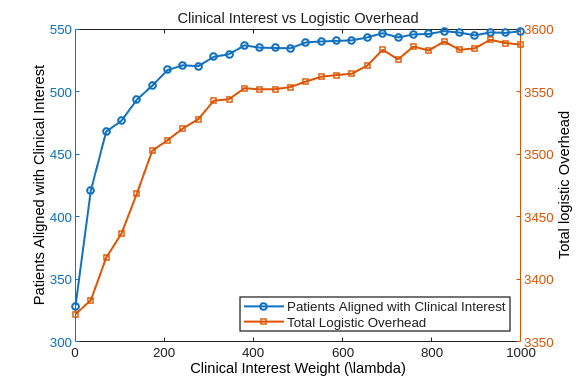


figure('Units', 'inches', 'Position', [1, 1, 6, 4]);  % Figure size suitable for journal

yyaxis left
plot(lambda, alignedPatients, '-o', 'LineWidth', 1.5, 'MarkerSize', 5);
ylabel('Patients Aligned with Clinical Interest', 'FontSize', 12, 'Color', 'k');

yyaxis right
plot(lambda, nonLocalShipments, '-s', 'LineWidth', 1.5, 'MarkerSize', 5);
ylabel('Total logistic Overhead', 'FontSize', 12, 'Color', 'k');

xlabel(['Clinical Interest Weight (', '\lambda', ')'], 'FontSize', 12, 'FontName', 'Arial', 'Color', 'k');

legend({'Patients Aligned with Clinical Interest', 'Total Logistic Overhead'}, ...
    'Location', 'southeast', 'FontSize', 10);

title('Clinical Interest vs Logistic Overhead', ...
      'FontSize', 16, 'FontWeight', 'normal');

% Set axis properties
set(gca, 'FontName', 'Arial', 'FontSize', 10);

grid off;
box on;

set(gcf, 'Color', 'w');  % White background for EPS

% Save as high-resolution EPS
print(gcf, '-depsc2', '-r600', fullfile(graphicFolder, 'clinical_interest_tradeoff.eps'));

## Model comparison: Heuristic Strategy

Y = zeros(m,n); % Y(i,j): # of patients allocated disease i / hosp j
hospitalRem = HCPpatientNumberUB';

for i = 1:m
    diseasePreval = D(i,:);
    totalAvail    = sum(diseasePreval);
    if totalAvail == 0, continue; end

    % Weighted prevalence + clinical interest
    base = diseasePreval ./ max(eps, totalAvail);
    wts  = base + clinicalInterestMat(i,:)*0.3;  % e.g. add +0.3 if that HCP is interested
    wts  = wts / sum(wts);  % normalize

    rawAlloc = round( wts * patientNumberUB(i) );

    feasible = min(rawAlloc, diseasePreval);
    feasible = min(feasible, hospitalRem);

    assigned  = sum(feasible);
    remaining = patientNumberUB(i) - assigned;

    while remaining > 0
        candidates = (diseasePreval > feasible) & (hospitalRem > feasible);

        % If no hospital can add patients at all, break
        if ~any(candidates)
            break;
        end

        % 'canImprove' = how many more can be assigned (or is it just 1?),
        % but we can use diseasePreval - feasible as a proxy for "unused prevalence".
        canImprove = (diseasePreval - feasible) .* candidates;

        [bestVal, bestH] = max(canImprove);

        % If bestVal is 0 => can't improve further
        if bestVal <= 0
            break;
        end

        % Otherwise, assign one more patient
        feasible(bestH) = feasible(bestH) + 1;
        hospitalRem(bestH) = hospitalRem(bestH) - 1;
        remaining = remaining - 1;
    end


    % update
    Y(i,:) = feasible;
    hospitalRem = hospitalRem - feasible;
end

y = sum(Y,2); % total recruited per disease
z = sum(Y,1); % total recruited per hospital

assert(all(z' <= HCPpatientNumberUB + 1e-9), 'Capacity exceeded?');
fprintf('Recruited total patients = %d\n', sum(y));

Recruited total patients = 1115


    % 1) Determine which biomarkers are actually used => S = B * diag(y)
    S = B * diag(y);   % (p×m)
    neededBio = any(S > 0, 2);  % p×1: which biomarkers matter?

    % 2) Targeted set cover with coverage/cost ratio
    target_used = false(1,q);
    coveredT = false(p,1);
    while ~all(coveredT(neededBio))
        uncovered = neededBio & ~coveredT;
        % Among unused platforms, measure coverage/cost
        cand = ~target_used;
        coverage = sum(T(uncovered, cand), 1);  % how many new biomarkers each platform covers
        cost = r(cand);                         % cost of those candidate platforms

        % coverage/cost ratio
        ratio = coverage ./ max(eps, cost); 
        [bestVal, idxLocal] = max(ratio);
        if bestVal <= 0
            warning('No further coverage improvement for targeted. Breaking...');
            break;
        end

        cIndices = find(cand);
        bestPlat = cIndices(idxLocal);

        target_used(bestPlat) = true;
        coveredT = coveredT | (T(:,bestPlat)>0);
    end

    % 3) Global set cover w/ coverage/cost ratio
    global_used = false(1,w);
    coveredG = false(p,1);
    while ~all(coveredG(neededBio))
        uncovered = neededBio & ~coveredG;
        cand = ~global_used;
        coverage = sum(G(uncovered, cand), 1);
        costG = a(cand);

        ratio = coverage ./ max(eps, costG);
        [bestVal, idxLocal] = max(ratio);
        if bestVal <= 0
            warning('No further coverage improvement for global. Breaking...');
            break;
        end

        cIndices = find(cand);
        bestPlat = cIndices(idxLocal);

        global_used(bestPlat) = true;
        coveredG = coveredG | (G(:,bestPlat)>0);
    end

    fprintf('--- PLATFORM SELECTION ---\n');

--- PLATFORM SELECTION ---


    fprintf('Chosen targeted platforms: %d of %d\n', sum(target_used), q);

Chosen targeted platforms: 6 of 6


    fprintf('Chosen global   platforms: %d of %d\n', sum(global_used), w);

Chosen global   platforms: 7 of 7




%% (A) Suppose we already:
%    1) Recruited patients => Y, so that y = sum(Y,2).
%    2) Picked a "global" set of T-platforms (target_used) via coverage/cost ratio
%    3) Picked a "global" set of G-platforms (global_used)
% Then we want to build U(q×m) and H(w×m) so T*U ≥ S and G*H ≥ S hold.

% We'll do a mini-set-cover for each disease, with the chosen T or G, so that
% all biomarkers for disease d are covered.

% S = B * diag(y) => p×m, demanded biomarkers
% neededBio(disease) = B(:, disease)

U = zeros(q, m);  % # of samples on targeted platforms
H = zeros(w, m); % # of samples on global   platforms

for diseaseIdx = 1:m
    patCount = y(diseaseIdx);
    if patCount < 1
        continue;
    end

    %% 1) Subset of biomarkers needed for this disease
    neededBio = (B(:, diseaseIdx) == 1);   % p×1

    %% 2) Among the chosen T-platforms, do a mini set cover to ensure *all* neededBio are covered
    chosenT = find(target_used);          % e.g. [2, 4, 7] ...
    coveredLocal = false(sum(neededBio),1);   % track coverage of needed biomarkers only
    fullIndices = find(neededBio);            % actual row indices in T

    platformCoverage = T(neededBio, chosenT); % (sum(neededBio) × #chosenT)
    usedLocal = false(1, length(chosenT));    % which of the chosenT are used *for this disease*

    while ~all(coveredLocal)
        uncovered = ~coveredLocal;  % which biomarkers remain uncovered
        coverageCounts = sum(platformCoverage(uncovered,:), 1);

        % If no platform can cover more => break
        if all(coverageCounts==0)
            warning('Disease %d cannot be fully covered by chosen T platforms.', diseaseIdx);
            break;
        end

        [~, bestLoc] = max(coverageCounts);
        usedLocal(bestLoc) = true;

        % mark newly covered biomarkers        targetedColumn = [targetedColumn; targetedList'];

        newlyCovered = (platformCoverage(:, bestLoc) > 0);
        coveredLocal = coveredLocal | newlyCovered;
    end

    % Now all needed biomarkers for diseaseIdx are covered by the subset usedLocal
    % => Assign the entire patient count to each usedLocal platform
    for idxPlat = find(usedLocal)
        realPlat = chosenT(idxPlat);  % convert local index to real platform index
        U(realPlat, diseaseIdx) = patCount;
    end

    %% 3) Repeat mini set cover for global
    chosenG = find(global_used);
    coveredLocal = false(sum(neededBio),1);
    platformCoverage = G(neededBio, chosenG);
    usedLocal = false(1, length(chosenG));

    while ~all(coveredLocal)
        uncovered = ~coveredLocal;
        coverageCounts = sum(platformCoverage(uncovered,:), 1);

        if all(coverageCounts==0)
            warning('Disease %d cannot be fully covered by chosen G platforms.', diseaseIdx);
            break;
        end

        [~, bestLoc] = max(coverageCounts);
        usedLocal(bestLoc) = true;
        newlyCovered = (platformCoverage(:, bestLoc) > 0);
        coveredLocal = coveredLocal | newlyCovered;
    end

    for idxPlat = find(usedLocal)
        realPlat = chosenG(idxPlat);
        H(realPlat, diseaseIdx) = patCount;
    end
end

% (B) Summaries
targSamples = sum(U, 2)'; 
globSamples = sum(H, 2)';
targCost = sum(targSamples .* r);
globCost = sum(globSamples   .* a);
totalCost = targCost + globCost;

% (C) Check T*U >= S, G*H >= S
TU = T * U;  % p×m
GH = G * H;
if ~all(all(TU > S - 1e-9))
    error('T*U < S for some biomarker/disease => coverage fail');
end
if ~all(all(GH > S - 1e-9))
    error('G*H < S for some biomarker/disease => coverage fail');
end

fprintf('\n=== BASELINE w/ Per-disease mini set cover ===\n');


=== BASELINE w/ Per-disease mini set cover ===


fprintf('Total cost: %.2f\n', totalCost);

Total cost: 331935.00


## Model Comparison

% ========== Configuration ==========
max_hospitals = 24;
[m, n] = size(D);  % D = prevalence matrix, already defined in workspace
total_patients_heuristic = zeros(max_hospitals, 1);
total_patients_optimised = zeros(max_hospitals, 1);

% ========== Loop Over Number of HCPs ==========
for k = 1:max_hospitals
    selected_HCPs = 1:k;  % Select first k hospitals
    D_k = D(:, selected_HCPs);  % Subset prevalence
    n_k = length(selected_HCPs);  % Update size
    HCPcap_k = HCPpatientNumberUB(selected_HCPs);

    %% === HEURISTIC ALLOCATION ===
    Y = zeros(m, n_k);
    hospitalRem = HCPcap_k';
    for i = 1:m
        diseasePreval = D_k(i,:);
        totalAvail = sum(diseasePreval);
        if totalAvail == 0, continue; end

        wts = diseasePreval ./ max(eps, totalAvail);
        rawAlloc = round(wts * patientNumberUB(i));
        feasible = min(rawAlloc, diseasePreval);
        feasible = min(feasible, hospitalRem);

        assigned = sum(feasible);
        remaining = patientNumberUB(i) - assigned;

        while remaining > 0
            candidates = (diseasePreval > feasible) & (hospitalRem > feasible);
            if ~any(candidates), break; end
            canImprove = (diseasePreval - feasible) .* candidates;
            [bestVal, bestH] = max(canImprove);
            if bestVal <= 0, break; end
            feasible(bestH) = feasible(bestH) + 1;
            hospitalRem(bestH) = hospitalRem(bestH) - 1;
            remaining = remaining - 1;
        end

        Y(i,:) = feasible;
        hospitalRem = hospitalRem - feasible;
    end
    y_heuristic = sum(Y, 2);
    total_patients_heuristic(k) = sum(y_heuristic);

    %% === CARDINALITY OPTIMISED ALLOCATION ===
    % Build commutation matrix
    [I, J] = ndgrid(1:m, 1:n_k);
    p_idx = n_k * (I(:) - 1) + J(:);
    q_idx = m * (J(:) - 1) + I(:);
    Kmn = sparse(p_idx, q_idx, 1, m*n_k, m*n_k);

    % Matrices for constraints
    P_y = kron(ones(n_k, 1)', eye(m));
    P_z = kron(ones(m, 1)', eye(n_k)) * Kmn;

    LHS = [diag(D_k(:))     ,    -speye(m*n_k)     ,        zeros(m*n_k, m) ,        zeros(m*n_k, n_k); ...
           zeros(m, m*n_k)  ,    P_y               ,        -speye(m)       ,        zeros(m, n_k)    ; ...
           zeros(n_k, m*n_k),    P_z               ,        zeros(n_k, m)   ,        -speye(n_k)      ];

    % Problem setup
    variableSize = (m*n_k)*2 + m + n_k;
    lb = sparse(variableSize, 1);
    ub = 1e4 * ones(variableSize, 1);

    maxFeasiblePatients = sum(D_k, 2);
    lb(1:m*n_k) = 0;  ub(1:m*n_k) = 1;  % X variable
    lb(m*n_k+1:2*m*n_k) = 0;           % Y variableIMDLb .* (maxPatientsPerIMD >= IMDLb)
    lb(2*m*n_k+1:2*m*n_k+m) = 0;
    ub(2*m*n_k+1:2*m*n_k+m) = patientNumberUB;
    ub(2*m*n_k+m+1:end) = HCPcap_k(:);

    csense = repmat('E', m*n_k + m + n_k, 1);

    problem.p = false(variableSize, 1); problem.p(1:m*n_k) = true;
    problem.q = false(variableSize, 1); problem.q(2*m*n_k+1:2*m*n_k+m) = true;
    problem.r = ~(problem.p | problem.q);

    problem.A = LHS;
    problem.b = zeros(size(LHS,1), 1);
    problem.c = zeros(variableSize, 1);
    problem.csense = csense;
    problem.lb = lb;
    problem.ub = ub;

    % Objective
    problem.delta0 = 0;
    problem.delta1 = -1;

    % Solve
    param.printLevel = 0;
    solution = optimizeCardinality(problem, param);

    if isempty(solution.xyz)
        warning('Optimisation failed at HCP = %d', k);
        total_patients_optimised(k) = NaN;
    else
        y_opt = solution.xyz(2*m*n_k+1:2*m*n_k+m);
        total_patients_optimised(k) = sum(y_opt);
    end
end

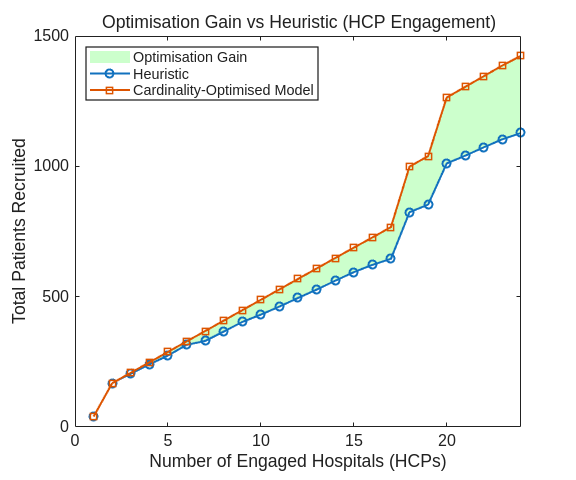


%% ========== Plotting ==========
figure('Units', 'inches', 'Position', [1, 1, 6, 5]);  % Figure size suitable for publication
x = (1:max_hospitals).';               % Ensure x is a column vector
th = total_patients_heuristic(:);      % Ensure data are column vectors
opt = total_patients_optimised(:);

% Create polygon coordinates for the filled area
x_fill = [x; flipud(x)];
y_fill = [th; flipud(opt)];

% Plot the filled area first (it will be at the back)
fill(x_fill, y_fill, [0, 1, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none'); hold on;

% Plot the lines on top
plot(x, th, '-o', 'LineWidth', 1.5);
plot(x, opt, '-s', 'LineWidth', 1.5);

set(gca, 'FontName', 'Arial', 'FontSize', 12);
xlabel('Number of Engaged Hospitals (HCPs)');
ylabel('Total Patients Recruited');
xlim([0, 24])

title('Optimisation Gain vs Heuristic (HCP Engagement)', ...
      'Units', 'normalized', 'FontWeight', 'normal');

legend('Optimisation Gain', 'Heuristic', 'Cardinality-Optimised Model ', ...
       'Location', 'northwest');
grid off;

% Save as high-resolution EPS
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, fullfile(graphicFolder, 'optimisation_vs_heuristic.eps'), 'Resolution', 600);

## Compare metabolomic cost for optimisation and Heuristic model

% Generate all combinations of row indices i and column indices j
[I, J] = ndgrid(1:m, 1:n);

% Compute the position indices in vec(A') and vec(A)
p_idx = n * (I(:) - 1) + J(:);  % Indices in vec(A')
q_idx = m * (J(:) - 1) + I(:);  % Indices in vec(A)

% Create the sparse commutation matrix
Kmn = sparse(p_idx, q_idx, ones(m * n, 1), m * n, m * n);

[p, q] = size(T);

% Generate a random number for number of global platforms
[p, w] = size(G);

clear problem 

% Defining left hand-side matrix
%   vec(X)  (m*n)               vec(Y)  (m*n)                y  (m*1)               z   (n*1)              vec(U)   (q*m)              vec(H)  (w*m)                     u (q*1)                        h (w*1)                  vec(S)  (m*p)               vec(beta)   (m*1)              vec(gamma)   (m*1)
LHS = [diag(D(:))   ,           -speye(m*n)     ,            sparse(m*n, m)     ,   sparse(m*n, n)    ,    sparse(m*n, m*q) ,          sparse(m*n, m*w) ,                sparse(m*n, q),                sparse(m*n, w),          sparse(m*n, m*p),           sparse(m*n, m),                sparse(m*n, m);...
    sparse(m, m*n)  ,           P_y             ,            -speye(m)          ,   sparse(m, n)      ,    sparse(m, m*q)   ,          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m)  ,                sparse(m, m)  ;...
    sparse(n, m*n)  ,           P_z             ,            sparse(n, m)       ,   -speye(n)         ,    sparse(n, m*q)   ,          sparse(n, m*w)   ,                sparse(n, q)  ,                sparse(n, w)  ,          sparse(n, m*p)  ,           sparse(n, m)  ,                sparse(n, m)  ;...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n)    ,    kron(speye(m), T),          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n)    ,    sparse(m*p, m*q) ,          kron(speye(m), G),                sparse(m*p, q),                sparse(m*p, w),          -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            kron(speye(m), B)*L,   sparse(m*p, n)    ,    sparse(m*p, m*q) ,          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),          -speye(m*p)     ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(q, m*n)  ,           sparse(q, m*n)  ,            sparse(q, m)       ,   sparse(q, n)      ,    P_u              ,          sparse(q, m*w)   ,                -speye(q)     ,                sparse(q, w)  ,          sparse(q, m*p)  ,           sparse(q, m)  ,                sparse(q, m)  ;...
    sparse(w, m*n)  ,           sparse(w, m*n)  ,            sparse(w, m)       ,   sparse(w, n)      ,    sparse(w, m*q)   ,          P_h              ,                sparse(w, q)  ,                -speye(w)     ,          sparse(w, m*p)  ,           sparse(w, m)  ,                sparse(w, m)  ;...    
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n)      ,    kron(speye(m), r),          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           -speye(m, m)  ,                sparse(m, m)  ;...
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n)      ,     sparse(m, m*q)  ,          kron(speye(m), a),                sparse(m, q)  ,                sparse(m, w)  ,          sparse(m, m*p)  ,           sparse(m, m)  ,                -speye(m, m)  ];


% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality
variableSize = (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1) + (m*p) + (m*1) + (m*1);
problem.p = false(variableSize, 1);
% ||vec(X)||_0
problem.p(1:(m*n)) = true;

% ||vec(U)||_0
problem.p((m*n) + (m*n) + m + n +1:(m*n) + (m*n) + m + n + (m*q)) = true;

% ||vec(H)||_0
problem.p((m*n) + (m*n) + m + n + (m*q) + 1:(m*n) + (m*n) + m + n + (m*q) + (m*w)) = true;

% Define q vector for one-norm cardinality
problem.q = false(variableSize, 1);

% ||(y)||_1
problem.q(2*m*n+1: 2*m*n+m+1) = true;

% ||beta||_1 + ||gamma||_1
problem.p(2*m*n + m + n + q*m + w*m + m*p + 1 : end) = true;

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = zeros(variableSize, 1);
% Relax the upper bound
ub = 10000 + zeros(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% Set number of patients per IMD to the half possible value y
% if       lb_y <  y  <  ub_y
% Then    -lb_y > -y  > -ub_y
% Assume minimum 15 patients per IMD
% Set number of patients to numbers calculated by Diagnostic Confidence Score
lb(m*n+m*n+1: m*n+m*n+m) = 0.5 * patientNumberLB;
ub(m*n+m*n+1: m*n+m*n+m) = patientNumberUB;

% Minimum 50 patients to be recruited at each hospital
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Set a cap on samples per site u
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + q) = repmat(2000, q, 1);

% Set a cap on samples per site h
ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1)) = repmat(2000, w, 1);

% Define csense
csense = [repmat('E', m*n+m+n, 1); repmat('G', 2*m*p, 1); repmat('E', q + w + m*p + 2*m, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;


solution = optimizeCardinality(problem, param);


optimizeCardinality objective data:

5122 min cardinality variables:
           0 mean(c(p))	           0 min(c(p))	           0 max(c(p))
           1 lambda0	           1 min(k)	           1 max(k)
       1e-06 lambda1	           1 min(o(p))	           1 max(o(p))

132 max cardinality variables:
           0 mean(c(q))	           0 min(c(q))	           0 max(c(q))
           1 delta0	           1 min(d)	           1 max(d)
       1e-06 delta1	           1 min(o(q))	           1 max(o(q))

27664 cardinality free variables:
           0 mean(c(r))	           0 min(c(r))	           0 max(c(r))
           0 alpha1	           0 min(o(r))	           0 max(o(r))

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
   1    0.50  9.9241e+05    -1.3e+03     5.8e+02           0         871     7.1e+02        0.42        -132    -1.3e+02     0.00081         NaN           

% Test the results
assert(~isempty(solution.xyz), 'Empty solution')

% Reshape the vectorised variables
% X
X_opt = solution.xyz(1:m*n);
X_opt = reshape(X_opt, m, n);

% Y
Y_opt = solution.xyz(m*n+1: 2*m*n);
Y_opt = reshape(Y_opt, m, n);

% y
y_opt = solution.xyz(2*m*n+1:2*m*n+m);
y_opt = reshape(y_opt, m, 1);

% z
z_opt = solution.xyz(2*m*n+m+1:2*m*n+m+n);
z_opt = reshape(z_opt, n, 1);

% U
U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
U_opt = reshape(U_opt, q, m);

% H
H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
H_opt = reshape(H_opt, w, m);

% S
S_opt = solution.xyz(2*m*n+m+n+m*q+m*w+1: 2*m*n+m+n+m*q+m*w+m*p);
S_opt = reshape(S_opt, p, m);

% Beta
beta_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+1: 2*m*n+m+n+m*q+m*w+m*p+m);
beta_opt = reshape(beta_opt, 1, m);

% Gamma
gamma_opt = solution.xyz(2*m*n+m+n+m*q+m*w+m*p+m+1: 2*m*n+m+n+m*q+m*w+m*p+2*m);
gamma_opt = reshape(gamma_opt, 1, m);


% Step 1: Recalculate total costs for Model B
targSamples_opt = sum(U_opt, 2);   % q×1
globSamples_opt = sum(H_opt, 2);   % w×1
costT_opt = sum(targSamples_opt .* r(:));
costG_opt = sum(globSamples_opt .* a(:));
totalCost_opt = costT_opt + costG_opt;

%% === (C) Determine required biomarkers -> Set cover for T & G ===
% =============== (C) Cost-Aware Set Cover for T & G =====================
[U_heur, H_heur, costT_heur, costG_heur, totalCost_heur] = HeuristicBaselineAllocation(y, T, G, r, a, B);
S = B * diag(y);   % p×m
%% Check feasibility: T*U ≥ S, G*H ≥ S
assert(all(all(T * U_heur >= S)), 'Targeted coverage assertion failed');
assert(all(all(G * H_heur >= S)), 'Global coverage assertion failed');

totalCost_heur

totalCost_heur = 591864

round(totalCost_opt)

ans = 419105

## Plot the results

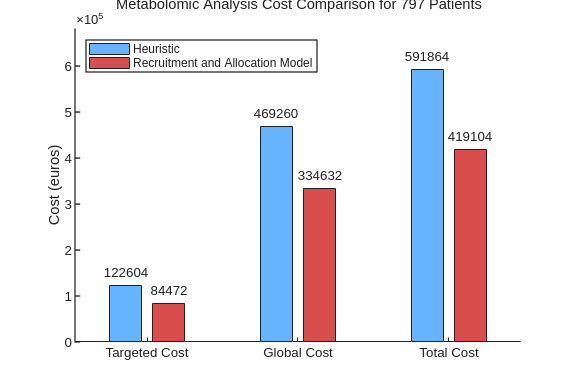


labels = {'Targeted Cost','Global Cost','Total Cost'};
heuristic_costs  = [costT_heur, costG_heur, totalCost_heur];
optimised_costs = [costT_opt, costG_opt, totalCost_opt];

x = 1:numel(labels);
bar_width = 0.75;  % optional: controls individual bar width

figure('Units','inches','Position',[1,1,6,4]);
hold on;

cost = [heuristic_costs; optimised_costs];  % 2-by-3 matrix
b = bar(x, cost', bar_width);  % transpose for grouped bar chart

% Appearance
b(1).FaceColor = [0.4 0.7 1];   % light blue
b(2).FaceColor = [0.85, 0.3, 0.3];  % soft red

% Axis settings
ylabel('Cost (euros)');
set(gca, 'XTick', x, 'XTickLabel', labels);
title(sprintf('Metabolomic Analysis Cost Comparison for %d Patients', round(sum(y_opt))), ...
      'FontSize', 12, 'Units', 'normalized', 'Position', [0.5,1.05,0], 'FontWeight', 'normal');
legend('Heuristic', 'Recruitment and Allocation Model', 'Location', 'northwest');
ylim([0, max([heuristic_costs, optimised_costs]) * 1.15]);
set(gca, 'FontName', 'Arial', 'FontSize', 10);
grid off;

% Add value labels above bars
yoff = max([heuristic_costs, optimised_costs]) * 0.02;
for i = 1:2  % for both groups: heuristic and optimised
    x_endpoints = b(i).XEndPoints;
    y_endpoints = b(i).YEndPoints;
    values = cost(i, :);
    for j = 1:numel(x_endpoints)
        text(x_endpoints(j), y_endpoints(j) + yoff, sprintf('%.0f', values(j)), ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);
    end
end

set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, fullfile(graphicFolder, 'metabolomic_cost_opt_vs_heu.png'), 'Resolution', 600);


% ======== PLOTTING COST COMPARISON ==========
labels = {'Targeted Cost', 'Global Cost', 'Total Cost'};
heuristic_costs = [costT_heur, costG_heur, totalCost_heur];



$$%% Optimization Problem

% Objective:
\[
\text{min} \quad 
\left\| X \right\|_0 
+ \left\| U \right\|_0 
+ \left\| H \right\|_0 
+ \| \beta \|_1 
+ \| \gamma \|_1
+ \| W \|_1 
+ \| F \|_1 
\]
$$



$$% Subject to:
\text{s.t:}
\[
\text{diag(vec}(\mathbf{D})) \cdot \text{vec}(X) = \text{vec}(Y),
\]
\[
(\mathbf{{1}_{n}^{\mathrm{T}} \otimes I_{m}}) \cdot \mathrm{vec}(Y) = y
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{n}}) \cdot \mathbf{K_{mn}} \cdot \mathrm{vec}(Y) = z
\]
\[
(\mathbf{I}_m \otimes \mathbf{T}) \cdot \text{vec}(U) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{G}) \cdot \text{vec}(H) \geq 2\text{vec}(S),
\]
\[
(\mathbf{I}_m \otimes \mathbf{B}) \cdot \mathbf{L} \cdot y = \text{vec}(S),
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{q}}) \cdot \mathrm{vec}(U) = u
\]
\[
(\mathbf{{1}_{m}^{\mathrm{T}} \otimes I_{w}}) \cdot \mathrm{vec}(H) = h
\]
\[
(\mathbf{I}_m \otimes \mathbf{r}) \cdot \text{vec}(U) = \text{vec}(\beta),
\]
\[
(\mathbf{I}_m \otimes \mathbf{a}) \cdot \text{vec}(H) = \text{vec}(\gamma),
\]
\[
\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U) \leq \text{vec}(F),
\]
\[
-\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)+\mathbf{\mathbf{A_{\mathit{(m.t)\times(m.q)}}}}\cdotp\mathbf{K}_{qm}\cdotp\mathrm{vec}(U) \leq \text{vec}(F),
\]
\[
\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)-\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H) \leq \text{vec}(W),
\]
\[
-\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.n)}}}}\cdotp\mathrm{vec}(Y)+\mathbf{\mathbf{A_{\mathit{(m.g)\times(m.w)}}}}\cdotp\mathbf{K}_{wm}\cdotp\mathrm{vec}(H) \leq \text{vec}(W),
\]
\[
0 \leq X \leq 1,
\]
\[
lb_y \leq y \leq ub_y,
\]
\[
lb_z \leq z \leq ub_z,
\]
\[
lb_u \leq u \leq ub_u,
\]
\[
lb_h \leq h \leq ub_h.
\$$


## Compare metabolomic cost for Model B and Heuristic model

% Generate all combinations of row indices i and column indices j
[I, J] = ndgrid(1:m, 1:n);

% Compute the position indices in vec(A') and vec(A)
p_idx = n * (I(:) - 1) + J(:);  % Indices in vec(A')
q_idx = m * (J(:) - 1) + I(:);  % Indices in vec(A)

% Create the sparse commutation matrix
Kmn = sparse(p_idx, q_idx, ones(m * n, 1), m * n, m * n);

[p, q] = size(T);
[~, w] = size(G);

% Define a cap for analysis capacity for each omics site
P_u = kron(ones(m, 1)', eye(q));
P_h = kron(ones(m, 1)', eye(w));

% Check the variables
assert(all(P_u*round(U_opt(:)) == sum(round(U_opt),2)))
assert(all(P_h*round(H_opt(:)) == sum(round(H_opt),2)))


clear problem 

% Defining left hand-side matrix
%   vec(X)  (m*n)               vec(Y)  (m*n)                y  (m*1)               z   (n*1)              vec(U)   (q*m)              vec(H)  (w*m)                     u (q*1)                        h (w*1)                    vec(S)  (m*p)               vec(beta)   (m*1)              vec(gamma)   (m*1)
LHS = [diag(D(:))   ,           -speye(m*n)     ,            sparse(m*n, m)     ,   sparse(m*n, n)    ,    sparse(m*n, m*q) ,          sparse(m*n, m*w) ,                sparse(m*n, q),                sparse(m*n, w),            sparse(m*n, m*p),           sparse(m*n, m),                sparse(m*n, m);...
    sparse(m, m*n)  ,           P_y             ,            -speye(m)          ,   sparse(m, n)      ,    sparse(m, m*q)   ,          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)  ,            sparse(m, m*p)  ,           sparse(m, m)  ,                sparse(m, m)  ;...
    sparse(n, m*n)  ,           P_z             ,            sparse(n, m)       ,   -speye(n)         ,    sparse(n, m*q)   ,          sparse(n, m*w)   ,                sparse(n, q)  ,                sparse(n, w)  ,            sparse(n, m*p)  ,           sparse(n, m)  ,                sparse(n, m)  ;...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n)    ,    kron(speye(m), T),          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),            -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            sparse(m*p, m)     ,   sparse(m*p, n)    ,    sparse(m*p, m*q) ,          kron(speye(m), G),                sparse(m*p, q),                sparse(m*p, w),            -2*speye(m*p)   ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(m*p, m*n),           sparse(m*p, m*n),            kron(speye(m), B)*L,   sparse(m*p, n)    ,    sparse(m*p, m*q) ,          sparse(m*p, m*w) ,                sparse(m*p, q),                sparse(m*p, w),            -speye(m*p)     ,           sparse(m*p, m),                sparse(m*p, m);...
    sparse(q, m*n)  ,           sparse(q, m*n)  ,            sparse(q, m)       ,   sparse(q, n)      ,    P_u              ,          sparse(q, m*w)   ,                -speye(q)     ,                sparse(q, w)  ,            sparse(q, m*p)  ,           sparse(q, m)  ,                sparse(q, m)  ;...
    sparse(w, m*n)  ,           sparse(w, m*n)  ,            sparse(w, m)       ,   sparse(w, n)      ,    sparse(w, m*q)   ,          P_h              ,                sparse(w, q)  ,                -speye(w)     ,            sparse(w, m*p)  ,           sparse(w, m)  ,                sparse(w, m)  ;...    
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n)      ,    kron(speye(m), r),          sparse(m, m*w)   ,                sparse(m, q)  ,                sparse(m, w)               sparse(m, m*p)  ,           -speye(m, m)  ,                sparse(m, m)  ;...
    sparse(m, m*n)  ,           sparse(m, m*n)  ,            sparse(m, m)       ,   sparse(m, n)      ,     sparse(m, m*q)  ,          kron(speye(m), a),                sparse(m, q)  ,                sparse(m, w)               sparse(m, m*p)  ,           sparse(m, m)  ,                -speye(m, m)  ];


% Define Optimise Cardinality problem:
% Define p, vector for zero-norm cardinality
variableSize = (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1) + (m*p) + (m*1) + (m*1);
problem.p = false(variableSize, 1);
% ||vec(X)||_0
problem.p(1:(m*n)) = true;

% ||vec(U)||_0
problem.p((m*n) + (m*n) + m + n +1:(m*n) + (m*n) + m + n + (m*q)) = true;

% ||vec(H)||_0
problem.p((m*n) + (m*n) + m + n + (m*q) + 1:(m*n) + (m*n) + m + n + (m*q) + (m*w)) = true;

% Define q vector for one-norm cardinality
problem.q = false(variableSize, 1);

% ||(y)||_1
problem.q(2*m*n+1: 2*m*n+m+1) = true;

% ||beta||_1 + ||gamma||_1
problem.p((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1) + (m*p) + 1 : end) = true;

% Define r
problem.r = ~(problem.p + problem.q);

% Define bounds
lb = zeros(variableSize, 1);
% Relax the upper bound
ub = 10000 + zeros(variableSize, 1);

% set the lower bounds for X variable
lb(1:(m*n)) = 0;
ub(1:(m*n)) = 1;

% Set number of patients per IMD to the half possible value y
% if       lb_y <  y  <  ub_y
% Then    -lb_y > -y  > -ub_y
% Assume minimum 15 patients per IMD
% Set number of patients to numbers calculated by Diagnostic Confidence Score
lb(m*n+m*n+1: m*n+m*n+m) = 0.5 * patientNumberLB;
ub(m*n+m*n+1: m*n+m*n+m) = patientNumberUB;


% Minimum 50 patients to be recruited at each hospital
ub(m*n+m*n+m+1: m*n+m*n+m+n) = HCPpatientNumberUB;

% Define csense
csense = [repmat('E', m*n+m+n, 1); repmat('G', 2*m*p, 1); repmat('E', q + w + m*p + 2*m, 1)];
problem.p = logical(problem.p);
problem.q = logical(problem.q);
problem.r = logical(problem.r);
problem.A = LHS;
problem.b = zeros(size(problem.A, 1), 1);
problem.ub = ub;
problem.lb = lb;
problem.c = zeros(size(problem.A,2),1);
problem.csense = csense;
param.printLevel=1;

targeted_caps = 0:200:2000;
global_caps = 0:200:2000;

for i = 1:numel(global_caps)
    for j = 1:numel(targeted_caps)
        gc = global_caps(i);
        tc = targeted_caps(j);
        opt_feasible = true;
        heur_feasible = true;

        % Set a cap on samples per site u
        problem.ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + q) = repmat(tc, q, 1);

        % Set a cap on samples per site h
        problem.ub((m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + 1: (m*n) + (m*n) + m + n + (m*q) + (m*w) + (q*1) + (w*1)) = repmat(gc, w, 1);

        try
            solution = optimizeCardinality(problem, param);
            % U
            U_opt = solution.xyz(2*m*n+m+n+1: 2*m*n+m+n+m*q);
            U_opt = reshape(U_opt, q, m);

            % H
            H_opt = solution.xyz(2*m*n+m+n+m*q+1: 2*m*n+m+n+m*q+m*w);
            H_opt = reshape(H_opt, w, m);
            targSamples_opt = sum(U_opt, 2);   % q×1
            globSamples_opt = sum(H_opt, 2);   % w×1
            costT_opt = sum(targSamples_opt .* r(:));
            costG_opt = sum(globSamples_opt .* a(:));
            totalCost_opt = costT_opt + costG_opt;

        catch
            opt_feasible = false;
        end

        try
            [U_heur, H_heur, costT_heur, costG_heur, totalCost_heur] = HeuristicBaselineAllocation(y, T, G, r, a, B, repmat(tc, q, 1), repmat(gc, w, 1));
        catch
            heur_feasible = false;
        end

        % Encode feasibility status
        if opt_feasible && heur_feasible
            feasibility_map(i,j) = 0;  % both feasible
        elseif opt_feasible && ~heur_feasible
            feasibility_map(i,j) = 1;  % only optimisation feasible
        elseif ~opt_feasible && heur_feasible
            error('Heuristic model reached a feasible solution where the optimisation did not')
        else
            feasibility_map(i,j) = 2;  % both infeasible
        end

    end
end

 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0        a(y)      ||y||1      c(x,y)      ||z||1                 sec
 itn     theta    ||dx||     del_obj         obj      linear      ||x||0        a(x)      ||x||1      ||y||0       

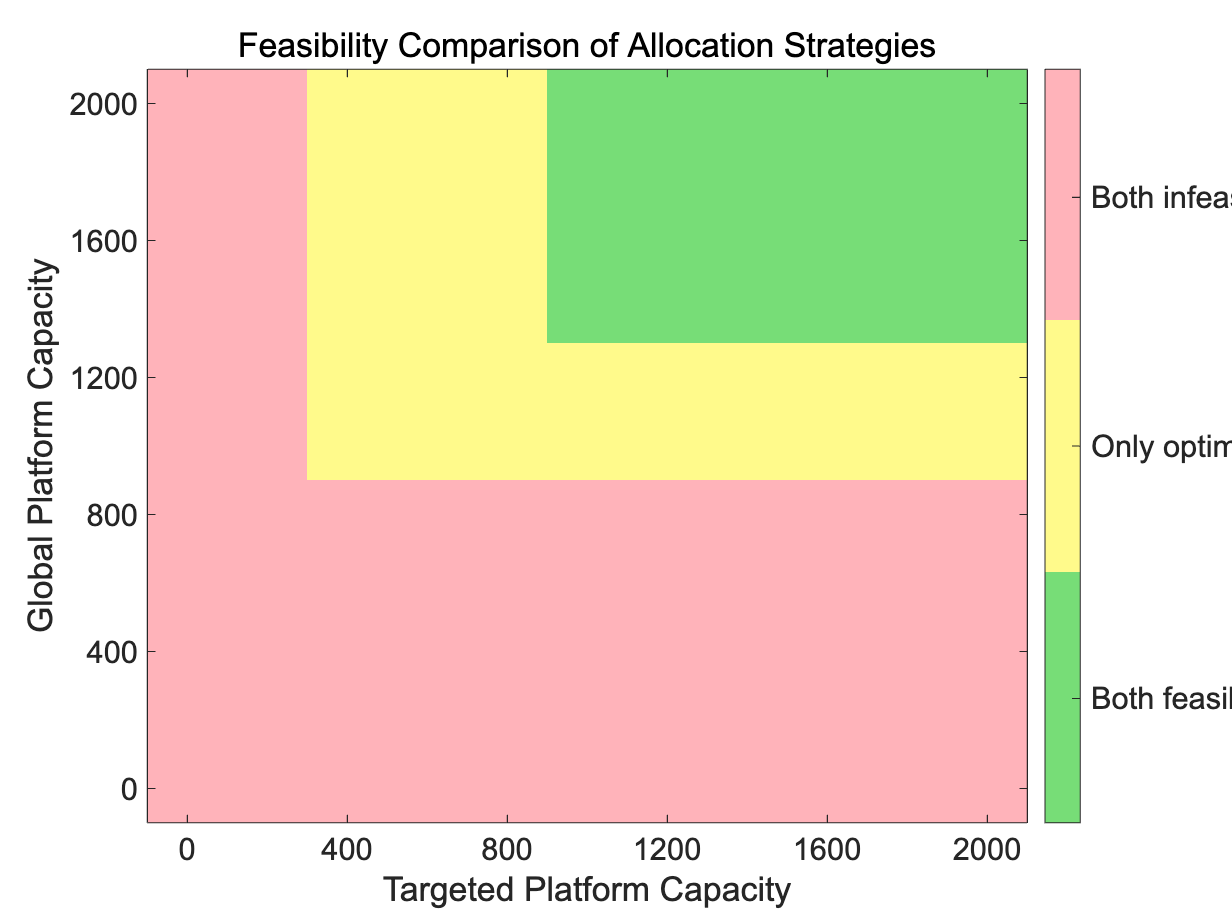

%% ===== Feasibility Map =====
figure;

% Create the feasibility map (replace with actual data)
imagesc(targeted_caps, global_caps, feasibility_map);

% Use pastel colours: pastel green, yellow, red
colormap([119, 221, 119; 255, 250, 139; 255, 179, 186] / 255); 

% Set up colour bar
colorbar('Ticks', [0.33, 1, 1.66], ...
         'TickLabels', {'Both feasible', 'Only optimisation feasible', 'Both infeasible'}, ...
         'FontSize', 14);
drawnow

% Label axes and title
xlabel('Targeted Platform Capacity', 'FontSize', 14, 'FontName', 'Arial');
ylabel('Global Platform Capacity', 'FontSize', 14, 'FontName', 'Arial');
title('Feasibility Comparison of Allocation Strategies', 'FontSize', 16, 'FontName', 'Arial', 'FontWeight', 'normal');

% Adjust axis
set(gca, 'YDir', 'normal');
% Use tight layout adjustment
%set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.01));

% Ticks for better readability (optional)
xticks(0:400:max(targeted_caps));
yticks(0:400:max(global_caps));

% Export settings
%set(gcf, 'PaperPositionMode', 'auto');
set(gca, 'FontName', 'Arial', 'FontSize', 14);

exportgraphics(gcf, fullfile(graphicFolder, 'feasibility_comparison.eps'), 'ContentType', 'vector', 'Resolution', 600);